# Trabajo Final Inteligencia Artificial I – año 2021: Visión Artifical

**Alumno:** Tassara Renzo

**Legajo: **12299

**Profesora titular:** Dra. Ing. Selva Soledad Rivera

**Jefe de Trabajos Prácticos:**   Ing. Juan I. García

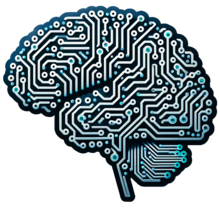

## Resumen

    Este informe presenta un enfoque para el reconocimiento de imágenes de tornillos, tuercas, arandelas y clavos utilizando los algoritmos Knn y Kmeans. Antes de aplicar estos algoritmos de clasificación, se lleva a cabo un preprocesamiento de las imágenes mediante la aplicación de diversos filtros para mejorar la calidad de los datos.

    El algoritmo Knn (vecinos más cercanos) se utiliza para clasificar las imágenes basándose en la similitud con ejemplos de entrenamiento previamente etiquetados. Por otro lado, el algoritmo Kmeans agrupa las imágenes en clústeres basándose en la similitud de sus características.

    Además del reconocimiento de objetos, se presenta un algoritmo de planificación STRIPS (STRIPS Planning System). Este algoritmo se utiliza para la planificación de tareas, específicamente para optimizar el reordenamiento de las piezas. STRIPS permite modelar el entorno y las acciones posibles de una manera formal, lo que facilita la búsqueda de la secuencia de acciones óptima para alcanzar un objetivo dado.

    Finalmente se realiza un algoritmo A* (A estrella), el cual tiene como objetivo reubicar todas las piezas en otro lugar utilizando el camino más óptimo, teniendo en cuenta los obstáculos que pueden aparecer y utilizando la distancia de Manhattan.

## Introducción

    La visión artificial es una rama de la inteligencia artificial que se centra en el desarrollo de sistemas capaces de interpretar y comprender el contenido visual del mundo que los rodea. Utilizando algoritmos y técnicas computacionales, la visión artificial permite a las máquinas procesar y analizar imágenes de manera similar a como lo hacen los seres humanos.

    El problema que abordaremos en este informe es el reconocimiento y la clasificación automatizados de objetos en imágenes, con el objetivo específico de identificar y categorizar tornillos, tuercas, arandelas y clavos en un entorno industrial.

    Para lograr dicho reconocimiento, se necesitó aplicar diferentes filtros a la imagen, calcular sus características, armar una base de datos con dichas características y luego analizar una imagen con los algoritmos Knn y Kmeans.

    El algoritmo K-means, un método de agrupamiento no supervisado, es ampliamente utilizado en el análisis de datos para la clasificación y la identificación de patrones. Este algoritmo tiene la ventaja de ser simple pero potente, permitiendo clasificar rápidamente grandes volúmenes de datos en grupos o "clusters" basados en sus características. Sin embargo, como se verá más adelante, este algoritmo tiene un poco de supervisación, ya que los centroides iniciales para comenzar a iterar son cercanos a los centroides correspondientes.

    Por otro lado, tenemos el algoritmo K-nn o K-Nearest Neighbors, un método de clasificación supervisado, que clasifica los elementos en base a la proximidad a los vecinos más cercanos en el espacio de características.

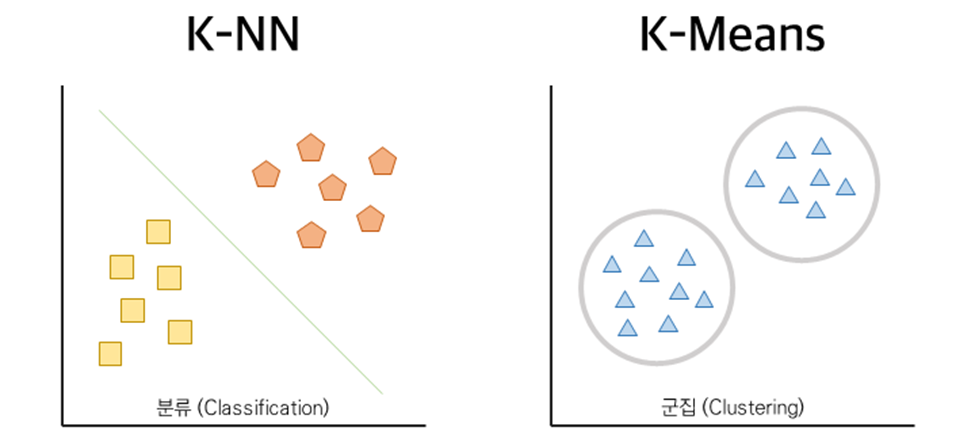

    Una vez reconocidos los elementos, se necesitará reorganizar dichos elementos de la manera más eficiente posible. Para esto se utiliza el lenguaje STRIPS (Stanford Research Institute Problem Solver). STRIPS es un lenguaje formal para la planificación de acciones, es decir, permite describir un estado inicial, un estado objetivo y un conjunto de acciones posibles. Utilizando STRIPS, podemos determinar una secuencia de acciones que nos lleve del estado inicial al estado objetivo, proporcionando una solución para la reorganización de las cajas.

    Luego se necesita reubicar este conjunto de elementos en otra ubicación del lugar donde se encuentran (en este caso es dentro del aula) buscando el camino más optimo utilizando el algoritmo A*. Este es un algoritmo de búsqueda informada que utiliza una heurística, en nuestro caso la Distancia de Manhattan, para encontrar el camino más corto en un mapa o gráfico. A* es ampliamente conocido por su eficiencia y precisión, siendo una elección popular para problemas de rutas y navegación.

## Explicación General para el usuario

    Primero se deberá elegir entre las opciones "Analizar_imagen", "Entrenar_IA" o "Comparar_Filtros" las cuales se explican a continuacion:

- Analizar_Imagen: Se ejecuta el código para analizar la imagen cargada y se usará el algoritmo Knn o Kmeans dependiendo que haya elegido el usuario para implementar (esta eleccion se hace cambiando la variable "algoritmo")

- Entrenar_IA: Se ejecuta el código para hacer los calculos necesarios para luego poder guardarlos en una base de datos y poder ser utilizados en futuras decisiones. El usuario deberá informarle al algoritmo a que elemento le corresponde cada imagen.

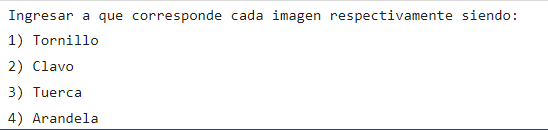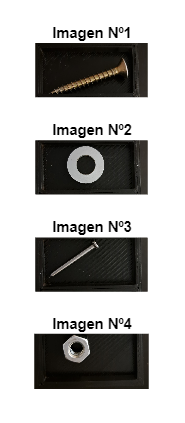

- Comparar_Filtros: Muestra todos los filtros que pueden ser utilizados unos al lado del otro para tener una mejor visualizacion de estos

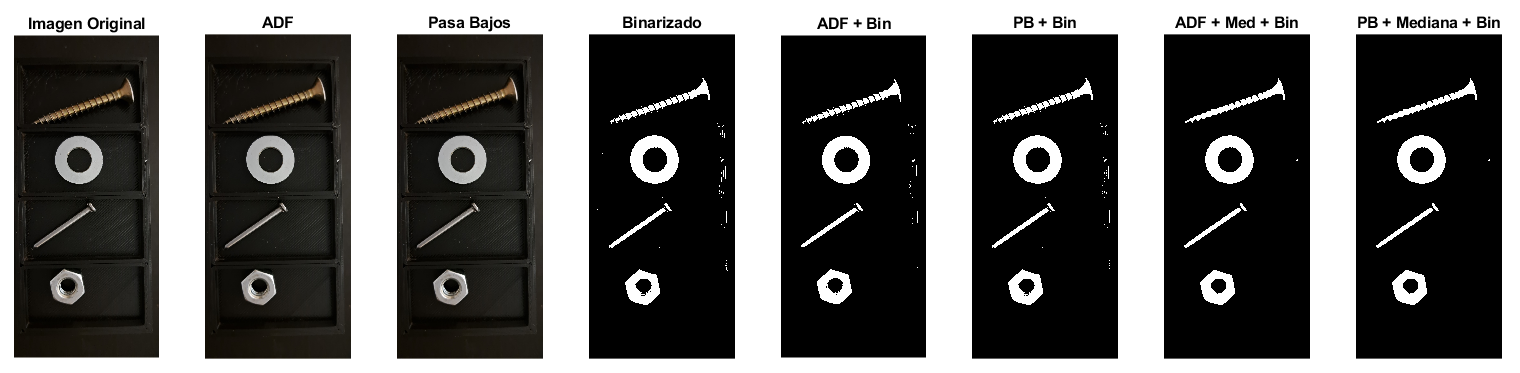

    Luego se elige el filtro a utilizar. Estos pueden ser:

- Anisotrópico (ADF)

- Pasa Bajo (PB)

- Binarización (Bin)

- ADF + Binarización

- Pasa Bajo + Binarización

- ADF + Mediana + Binarización

- Pasa Bajo + Mediana + Binarización

    Si el usuario desea una ejecución más rápida del código, podrá deshabilitar los gráficos y solo mostrar el resultado de la imagen a analizar.

## Diseño del agente

    Para realizar este trabajo, se dividió el agente en tres partes:

- Algoritmo de reconocimiento de pieza (Knn y Kmeans);

- Algoritmo para reacomodar las piezas (STRIPS);

- Algoritmo para reubicar todo el conjunto de piezas (A*)

## Algoritmo de reconocimiento de pieza

    En esta sección se explicará con detalle cómo se realizó el reconocimiento de imagen para identificar si la imagen se trata de un clavo, una tuerca, una arandela o un tornillo. Para realizar este procesos se utilizaron filtros frecuenciales y espaciales para procesar la imagen y los algoritmos Knn y Kmeans se utilizaron para tomar una decisión final.

    Este algoritmo fue programado en Matlab, y se realizó en Scripts y en Live Scripts. Se optó por mostrar en este informe Live Scripts porque tiene una estructura más ordenada y se puede manejar de forma muy interactiva utilizando las herramientas de control dentro de Matlab. Además es posible agregar textos entre secciones del código sin utilizar comentarios.

    Para tener una idea general de cómo funciona el algoritmo, a continuación se muestra un diagrama de bloques de dicho proceso.

    Para que el reconocimiento de imagen se la más eficiente posible, se tendrán que tener en cuenta las siguiente condiciones al momento de capturar la imagen:

- **Iluminación regulada y constante**, para que los cambios captados por el sistema se deban a cambios en los objetos inspeccionados y no a los cambios en la fuente de luz.

- **Objetos correctamente situados**, se deben colocar los objetos delante de la cámara sin obstrucciones ni cambios en la distancia focal.

- **Configuración de la cámara**. Para que el código funcione correctamente y haga el recorte de la imagen como corresponde, la imagen debe tener una dimensión de  1873 x 4160 píxeles. Además se sabe que el algoritmo funciona correctamente al capturar la imagen con un celular Sansung A53, seleccionando la opcion “Full Screen”, en 64M y enviando la imagen a la computadora por medio de WhatsApp en HD.

- **Procesamiento de imagen**, deben utilizarse métodos de filtrado adecuados para el entorno y el tipo de objeto a analizar.

- **Base de datos**, el sistema debe contar con una base de datos lo suficientemente amplia para asegurar cierta precisión. De no ser así, el usuario podrá cargar su propia base de datos o agregar información a la ya existente.

## Código

### ***Main***

    Dentro del main, se eligen diferentes opciones y parámetros a usar para llevar a cabo la ejecución del código.

Variables

opcion = 1;
filtro = 7;
plotear_todo = 1;
algoritmo = "Knn";

Constantes

vector_elemento = [0,0,0,0];

Cargado de imagen

%% ==== Imagen ====
%Propiedades de imagen: Full / 64M / HD al enviarlo por WP / Luz minima
imagen = imread('Prueba6.jpg'); %Imagen a importar

Error using imread>get_full_filename
File "Prueba6.jpg" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);


%[filas, columnas] = size(imagen);  %Descomentar para saber tamanio

Ingreso de opción del usuario (esta sección se usa en Matlab Scriptsa)

% %% ==== Procesamiento ====
% opcion = input("Ingrese el numero de la accion a realizar \n 1) Analizar imagen \n 2) Entrenar IA \n 3) Comparar filtros \n");
% while(opcion ~= 1 && opcion ~= 2 && opcion ~= 3)    %Error por si el usuario pone otro valor
%     opcion = input("Ingrese 1, 2 o 3 por favor: ");
% end

Si se entrena la IA, entonces se mostrará la imagen que quiere cargar a la base de datos

if (opcion == 2)
    figure;
    subplot(4,1,1);
    imshow(imagen(301:1200,:,:)), title('Imagen Nº1');
    subplot(4,1,2);
    imshow(imagen(1201:2100,:,:)), title('Imagen Nº2');
    subplot(4,1,3);
    imshow(imagen(2101:3000,:,:)), title('Imagen Nº3');
    subplot(4,1,4);
    imshow(imagen(3001:3900,:,:)), title('Imagen Nº4');
     
    disp("Ingresar a que corresponde cada imagen respectivamente siendo:");
    disp("1) Tornillo");
    disp("2) Clavo");
    disp("3) Tuerca");
    disp("4) Arandela");

    for(i = 1:4)
        vector_elemento(i) = input(['La imagen Nº', num2str(i), ' es: ']);
        while (vector_elemento(i) ~= 1 && vector_elemento(i) ~= 2 && vector_elemento(i) ~= 3 && vector_elemento(i) ~= 4)
            vector_elemento(i) = input(['Ingrese 1,2,3 o 4 \n La imagen Nº', num2str(i), ' es: ']);
        end
    end
    for (filtro = 1:7)
        disp(['Filtro Nº',num2str(filtro)]);
        Filtros(imagen, filtro, opcion,vector_elemento,plotear_todo,algoritmo);
    end

Si el usuario elige otra opción, se ejecuta la función Filtros()

else
    Filtros(imagen, filtro, opcion,vector_elemento,plotear_todo,algoritmo);
end

### ***Filtros***

    En esta función se realizan todos los filtros necesarios a la imagen

function Filtros(imagen, filtro, opcion,vector_elemento,plotear_todo,algoritmo)

Constantes: Se pueden variar dependiendo de las condiciones de la imagen (fondos, luminosidad, detalles, etc.)

- **umbral**: Al modificar esta variable, se modificará la "decisión" al momento de binarizar la imagen en escala de grises

- **m**: cantidad de pixeles cuadrados al momento de aplicar la mediana

- **Constante de mascara**

cte_mascara = 0.1111;  %1/9 funciona bien
mascara = cte_mascara*[1,1,1;1,1,1;1,1,1];
umbral = 0.3; %Valor optimo 0.3
m =  5; %Valor optimo 25
m = m^2;
n = m; %Valor optimo 25

#### Recorte de imagen

Se realiza un recorte de la imagen ya que se saca una sola foto de los cuatro elementos a la vez

Cada recorte tiene una dimensión de 900píxeles x 1873píxeles x 3

%% Muestra del recorte de imagen
if (opcion == 1 || opcion == 2)
    imagen1 = imagen(301:1200,:,:);
    imagen2 = imagen(1201:2100,:,:);
    imagen3 = imagen(2101:3000,:,:);
    imagen4 = imagen(3001:3900,:,:); 

#### Matrices RGB de cada imagen

La imagen original se guarda como una matriz tridimensional NxMxP:

- N = Cantidad de píxeles en X

- M = Cantidad de píxeles en Y

- P = Dimension correspondiente a cada color

    %% Red, Green, Blue
    matrizR_1 = imagen1(:,:,1); %matrices Red, Green, Blue primera parte de imagen
    matrizG_1 = imagen1(:,:,2);
    matrizB_1 = imagen1(:,:,3);
    
    matrizR_2 = imagen2(:,:,1); %matrices Red, Green, Blue segunda parte de imagen
    matrizG_2 = imagen2(:,:,2);
    matrizB_2 = imagen2(:,:,3);
    
    matrizR_3 = imagen3(:,:,1); %matrices Red, Green, Blue tercera parte de imagen
    matrizG_3 = imagen3(:,:,2);
    matrizB_3 = imagen3(:,:,3);
    
    matrizR_4 = imagen4(:,:,1); %matrices Red, Green, Blue cuarta parte de imagen
    matrizG_4 = imagen4(:,:,2);
    matrizB_4 = imagen4(:,:,3);  

#### Filtro anisotrópico

Para realizar este filtro, se utilizó la función "*imdiffusefilt*"

    %% ========== Filtro Anisotropico ============
    imagen_ADF_1(:,:,1)=imdiffusefilt(matrizR_1);
    imagen_ADF_1(:,:,2)=imdiffusefilt(matrizG_1);
    imagen_ADF_1(:,:,3)=imdiffusefilt(matrizB_1);
    
    imagen_ADF_2(:,:,1)=imdiffusefilt(matrizR_2);
    imagen_ADF_2(:,:,2)=imdiffusefilt(matrizG_2);
    imagen_ADF_2(:,:,3)=imdiffusefilt(matrizB_2);
    
    imagen_ADF_3(:,:,1)=imdiffusefilt(matrizR_3);
    imagen_ADF_3(:,:,2)=imdiffusefilt(matrizG_3);
    imagen_ADF_3(:,:,3)=imdiffusefilt(matrizB_3);
    
    imagen_ADF_4(:,:,1)=imdiffusefilt(matrizR_4);
    imagen_ADF_4(:,:,2)=imdiffusefilt(matrizG_4);
    imagen_ADF_4(:,:,3)=imdiffusefilt(matrizB_4);
    

#### Filtro Pasa Bajo

Para realizar este filtro, se utilizó la función "*filter2*"

    %% ========== Filtro Pasa Bajo ==============
    
    imagen_PB_1(:,:,1)=filter2(mascara,matrizR_1);
    imagen_PB_1(:,:,2)=filter2(mascara,matrizG_1);
    imagen_PB_1(:,:,3)=filter2(mascara,matrizB_1);
    
    imagen_PB_2(:,:,1)=filter2(mascara,matrizR_2);
    imagen_PB_2(:,:,2)=filter2(mascara,matrizG_2);
    imagen_PB_2(:,:,3)=filter2(mascara,matrizB_2);
    
    imagen_PB_3(:,:,1)=filter2(mascara,matrizR_3);
    imagen_PB_3(:,:,2)=filter2(mascara,matrizG_3);
    imagen_PB_3(:,:,3)=filter2(mascara,matrizB_3);
    
    imagen_PB_4(:,:,1)=filter2(mascara,matrizR_4);
    imagen_PB_4(:,:,2)=filter2(mascara,matrizG_4);
    imagen_PB_4(:,:,3)=filter2(mascara,matrizB_4);
    
    imagen_PB_1 = uint8(imagen_PB_1);   %Se pasan a valores entre 0 y 255
    imagen_PB_2 = uint8(imagen_PB_2);
    imagen_PB_3 = uint8(imagen_PB_3);
    imagen_PB_4 = uint8(imagen_PB_4);

#### Binarización

Para binarizar la imagen, primero se pasa la imagen RGB a una imagen en escala de grises utilizando la función "*rgb2gray*" y luego se binariza utilizando la función "*im2bw*".

    %% =========== Binarizacion ==========
    imagen_gris_1 = rgb2gray(imagen1); %Imagen en escala de grises
    imagen_binarizada_1 = im2bw(imagen_gris_1, umbral);
    imagen_gris_2 = rgb2gray(imagen2); %Imagen en escala de grises
    imagen_binarizada_2 = im2bw(imagen_gris_2, umbral);
    imagen_gris_3 = rgb2gray(imagen3); %Imagen en escala de grises
    imagen_binarizada_3 = im2bw(imagen_gris_3, umbral);
    imagen_gris_4 = rgb2gray(imagen4); %Imagen en escala de grises
    imagen_binarizada_4 = im2bw(imagen_gris_4, umbral);

#### Aplicacion de filtros individuales y combinados

Como se puede apreciar en el código, "imagen_filtrada" almacena las matrices de las imágenes filtradas para luego poder realizar los cálculos correspondientes

    if (filtro == 1)    %ADF
        imagen_filtrada = cat(3, imagen_ADF_1, imagen_ADF_2, imagen_ADF_3, imagen_ADF_4);
    elseif (filtro == 2)    %PB
        imagen_filtrada = cat(3, imagen_PB_1, imagen_PB_2, imagen_PB_3, imagen_PB_4);
    elseif (filtro == 3)    %Bin
        imagen_filtrada = cat(3, imagen_binarizada_1, imagen_binarizada_2, imagen_binarizada_3, imagen_binarizada_4);
    elseif(filtro == 4)   %ADF+Bin
        imagen_gris_ADF_1 = rgb2gray(imagen_ADF_1); %Imagen en escala de grises
        imagen_ADF_Bin_1 = im2bw(imagen_gris_ADF_1, umbral);
        imagen_gris_ADF_2 = rgb2gray(imagen_ADF_2); %Imagen en escala de grises
        imagen_ADF_Bin_2 = im2bw(imagen_gris_ADF_2, umbral);
        imagen_gris_ADF_3 = rgb2gray(imagen_ADF_3); %Imagen en escala de grises
        imagen_ADF_Bin_3 = im2bw(imagen_gris_ADF_3, umbral);
        imagen_gris_ADF_4 = rgb2gray(imagen_ADF_4); %Imagen en escala de grises
        imagen_ADF_Bin_4 = im2bw(imagen_gris_ADF_4, umbral);
        
        imagen_filtrada = cat(3, imagen_ADF_Bin_1, imagen_ADF_Bin_2, imagen_ADF_Bin_3, imagen_ADF_Bin_4);
    
    elseif(filtro == 5)   %PB+Bin
        imagen_gris_PB_1 = rgb2gray(imagen_PB_1); %Imagen en escala de grises
        imagen_PB_Bin_1 = im2bw(imagen_gris_PB_1, umbral);
        imagen_gris_PB_2 = rgb2gray(imagen_PB_2); %Imagen en escala de grises
        imagen_PB_Bin_2 = im2bw(imagen_gris_PB_2, umbral);
        imagen_gris_PB_3 = rgb2gray(imagen_PB_3); %Imagen en escala de grises
        imagen_PB_Bin_3 = im2bw(imagen_gris_PB_3, umbral);
        imagen_gris_PB_4 = rgb2gray(imagen_PB_4); %Imagen en escala de grises
        imagen_PB_Bin_4 = im2bw(imagen_gris_PB_4, umbral);
        
        imagen_filtrada = cat(3, imagen_PB_Bin_1, imagen_PB_Bin_2, imagen_PB_Bin_3, imagen_PB_Bin_4);
    
    elseif(filtro == 6) %ADF+mediana+Bin
        imagen_gris_ADF_1 = rgb2gray(imagen_ADF_1); %Imagen en escala de grises
        imagen_mediana_ADF_1 = medfilt2(imagen_gris_ADF_1, [m n]);
        imagen_ADF_mediana_Bin_1 = im2bw(imagen_mediana_ADF_1, umbral);
        imagen_gris_ADF_2 = rgb2gray(imagen_ADF_2); %Imagen en escala de grises
        imagen_mediana_ADF_2 = medfilt2(imagen_gris_ADF_2, [m n]);
        imagen_ADF_mediana_Bin_2 = im2bw(imagen_mediana_ADF_2, umbral);
        imagen_gris_ADF_3 = rgb2gray(imagen_ADF_3); %Imagen en escala de grises
        imagen_mediana_ADF_3 = medfilt2(imagen_gris_ADF_3, [m n]);
        imagen_ADF_mediana_Bin_3 = im2bw(imagen_mediana_ADF_3, umbral);
        imagen_gris_ADF_4 = rgb2gray(imagen_ADF_4); %Imagen en escala de grises
        imagen_mediana_ADF_4 = medfilt2(imagen_gris_ADF_4, [m n]);
        imagen_ADF_mediana_Bin_4 = im2bw(imagen_mediana_ADF_4, umbral);

        imagen_filtrada = cat(3, imagen_ADF_mediana_Bin_1, imagen_ADF_mediana_Bin_2, imagen_ADF_mediana_Bin_3, imagen_ADF_mediana_Bin_4);
    
    elseif(filtro == 7) %PB+mediana+Bin
        imagen_gris_PB_1 = rgb2gray(imagen_PB_1); %Imagen en escala de grises
        imagen_mediana_PB_1 = medfilt2(imagen_gris_PB_1, [m n]);
        imagen_bin_med_PB_1 = im2bw(imagen_mediana_PB_1, umbral);
        imagen_gris_PB_2 = rgb2gray(imagen_PB_2); %Imagen en escala de grises
        imagen_mediana_PB_2 = medfilt2(imagen_gris_PB_2, [m n]);
        imagen_bin_med_PB_2 = im2bw(imagen_mediana_PB_2, umbral);
        imagen_gris_PB_3 = rgb2gray(imagen_PB_3); %Imagen en escala de grises
        imagen_mediana_PB_3 = medfilt2(imagen_gris_PB_3, [m n]);
        imagen_bin_med_PB_3 = im2bw(imagen_mediana_PB_3, umbral);
        imagen_gris_PB_4 = rgb2gray(imagen_PB_4); %Imagen en escala de grises
        imagen_mediana_PB_4 = medfilt2(imagen_gris_PB_4, [m n]);
        imagen_bin_med_PB_4 = im2bw(imagen_mediana_PB_4, umbral);
    
        imagen_filtrada = cat(3, imagen_bin_med_PB_1, imagen_bin_med_PB_2, imagen_bin_med_PB_3, imagen_bin_med_PB_4);
    
    end
    if plotear_todo == 1
        subplot(4,2,1);
        imshow(imagen1), title('Original 1');
        subplot(4,2,3);
        imshow(imagen2), title('Original 2');
        subplot(4,2,5);
        imshow(imagen3), title('Original 3');
        subplot(4,2,7);
        imshow(imagen4), title('Original 4');
        subplot(4,2,2);
        imshow(imagen_filtrada(:,:,1)), title('Filtro 1');
        subplot(4,2,4);
        imshow(imagen_filtrada(:,:,2)), title('Filtro 2');
        subplot(4,2,6);
        imshow(imagen_filtrada(:,:,3)), title('Filtro 3');
        subplot(4,2,8);
        imshow(imagen_filtrada(:,:,4)), title('Filtro 4');
    end
        Funcion_Caracteristicas(imagen_filtrada,filtro,opcion,vector_elemento,plotear_todo,algoritmo);

elseif(opcion == 3)
    Comparacion_filtros(imagen,cte_mascara,umbral,m,n);
end
end

A continuacón se muestra el recorte de la imagen original junto con el recorte de la imagen filtrada

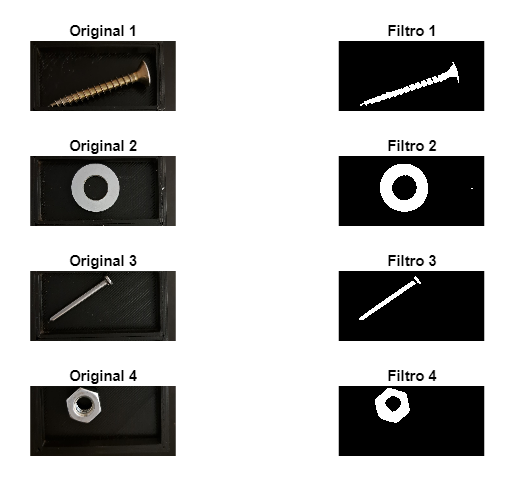

### ***Función características***

Dentro de esta funcion se calculan todas las caracteristicas necesarias para luego poder calcular las distancias euclidianas en los algoritmos Knn y Kmeans

function Funcion_Caracteristicas(imagen,filtro,opcion,vector_elemento,plotear_todo,algoritmo)

Constantes

[X,Y] = size(imagen(:,:,1));
P = 4;
Q = 4;
area = zeros(1,4);
perimetro = zeros(1,4);
Minicial = zeros(X, Y, 4);
Mcentrales = zeros(P, Q, 4);
Mnormales = zeros(P, Q, 4);
MHu = zeros(4,7);
circularidad = zeros(1,4);

#### Calculo de momentos iniciales

Para calculas los momento iniciales se utilizó la formula que se muestra a continuación:


$${}M_{\textrm{ij}}=\sum_X \sum_Y X^i Y^j I\left(X,Y\right)$$


Siendo:

- ${}M_{\textrm{ij}}$ = Momento inicial del pixel (i,j)

- $X$= Coordenada de cada pixel en X

- $Y$= Coordenada de cada pixel en X

- $I\left(X,Y\right)$ = Valor del pixel (X,Y)

for (k = 1:4)
    %% Momento inicial
    for (i = 0:1)
        for (j = 0:1)
            for (x = 1:X)
                for (y = 1:Y)
                    Minicial(i+1,j+1,k) = Minicial(i+1,j+1,k) + (x^i)*(y^j)*imagen(x,y,k);
                end
            end
        end
    end
    

#### Calculo de momentos centrales

Para calculas los momento centrales se utilizaron las fórmulas que se muestra a continuación:


$$\textrm{Centroides}=\;\textrm{Xraya},\textrm{Yraya}=\lbrace \frac{M_{10} }{M_{00} }\;,\frac{M_{01} }{M_{00} }\rbrace$$



$$\textrm{Momentos}\;\textrm{centrales}=\mu_{\textrm{pq}} =\sum_X \sum_Y {\left(X-\textrm{Xraya}\right)}^p {\left(Y-\textrm{Yraya}\right)}^q I\left(X,Y\right)$$


    %% Momentos centrales
    xraya = Minicial(2,1,k)/Minicial(1,1,k);
    yraya = Minicial(1,2,k)/Minicial(1,1,k);
    
    for (p = 0:(P-1))
        for (q = 0:(Q-1))
            for (x = 1:X)
                for (y = 1:Y)
                    Mcentrales(p+1,q+1,k) = Mcentrales(p+1,q+1,k) + ((x - xraya)^p)*((y - yraya)^q)*imagen(x,y,k);
                end
            end
        end
    end

#### Cálculo de momentos normales 

Para calculas los momentos normales se utilizó la formula que se muestra a continuación:


$$\eta_{\textrm{ij}} =\frac{\mu_{\textrm{ij}} }{{\mu_{00} }^{\left(1+\frac{i+j}{2}\right)} }$$


    %% Momentos normales
    for (p = 0:(P-1))
        for (q = 0:(Q-1))
                Mnormales(p+1,q+1,k) = Mcentrales(p+1,q+1,k)/(Mcentrales(1,1,k)^(1+(p+q)/2));
        end
    end

#### Cálculo de momentos de Hu

Para calcular los momentos de Hu se usaron las siguientes fórmulas:


$$\[
MHu(k,1) = Mn_{20} + Mn_{02}
\]
\[
MHu(k,2) = (Mn_{20} - Mn_{02})^2 + 4(Mn_{11})^2
\]
\[
MHu(k,3) = (Mn_{30} - 3Mn_{12})^2 + (3Mn_{21} - Mn_{03})^2
\]
\[
MHu(k,4) = (Mn_{30} + Mn_{12})^2 + (Mn_{21} + Mn_{03})^2
\]
\[
MHu(k,5) = (Mn_{30} - 3Mn_{12})(Mn_{30} + Mn_{12})((Mn_{30} + Mn_{12})^2 - 3(Mn_{21} + Mn_{03})^2) + (3Mn_{21} - Mn_{03})(Mn_{21} + Mn_{03})(3(Mn_{30} + Mn_{12})^2 - (Mn_{21} + Mn_{03})^2)
\]
\[
MHu(k,6) = (Mn_{20} - Mn_{02})((Mn_{30} + Mn_{12})^2 - (Mn_{21} + Mn_{03})^2) + 4Mn_{11}(Mn_{30} + Mn_{12})(Mn_{21} + Mn_{03})
\]
\[
MHu(k,7) = (3Mn_{21} - Mn_{03})(Mn_{30} + Mn_{12})((Mn_{30} + Mn_{12})^2 - 3(Mn_{21} + Mn_{03})^2) - (Mn_{30} - 3Mn_{12})(Mn_{21} + Mn_{03})(3(Mn_{30} + Mn_{12})^2 - (Mn_{21} + Mn_{03})^2)
\]$$


    %% Momentos invariantes de Hu
    Mn02 = Mnormales(1,3,k);
    Mn03 = Mnormales(1,4,k);
    Mn11 = Mnormales(2,2,k);
    Mn12 = Mnormales(2,3,k);
    Mn20 = Mnormales(3,1,k);
    Mn21 = Mnormales(3,2,k);
    Mn30 = Mnormales(4,1,k);
    
    MHu(k,1) = Mn20 + Mn02;
    MHu(k,2) = (Mn20 - Mn02)^2 + 4*(Mn11^2);
    MHu(k,3) = (Mn30 - 3*Mn12)^2 + (3*Mn21 - Mn03)^2;
    MHu(k,4) = (Mn30 + Mn12)^2 + (Mn21 + Mn03)^2;
    MHu(k,5) = (Mn30 - 3*Mn12)*(Mn30 + Mn12)*((Mn30 + Mn12)^2 - 3*(Mn21 + Mn03)^2) + (3*Mn21 - Mn03)*(Mn21 + Mn03)*(3*(Mn30 + Mn12)^2 - (Mn21 + Mn03)^2);
    MHu(k,6) = (Mn20 - Mn02)*((Mn30 + Mn12)^2 - (Mn21 + Mn03)^2) + 4*Mn11*(Mn30 + Mn12)*(Mn21 + Mn03);
    MHu(k,7) = (3*Mn21 - Mn03)*(Mn30 + Mn12)*((Mn30 + Mn12)^2 - 3*(Mn21 + Mn03)^2) - (Mn30 - 3*Mn12)*(Mn21 + Mn03)*(3*(Mn30 + Mn12)^2 - (Mn21 + Mn03)^2); 

#### Calculo de área 

Para realizar el cálculo del área de cada elemento se contaron la cantidad de píxeles con un valor de "1" de cada imagen.

%% ============ Area ============
    for(x = 1:X) 
        for(y = 1:Y)
            if (imagen(x,y,k) == 1)
                area(k) = area(k) + 1;
            end
        end
    end

#### Cálculo de perímetro

Para realizar el cálculo del perímetro, se usó la función "*bwboundaries*" el cual encuentra todos los perímetros de cada imagen. Luego se selecciona el mayor de esos perímetros. Esta selección permite luego calcular la circularidad de cada elemento y eliminar información innecesaria.

%% =============Perimetro===============
    perim = bwboundaries(imagen(:,:,k));    % Calcula los contornos de la imagen
    perim_mayor = perim{1}; % Inicializa el contorno más largo con el primer contorno encontrado
    for idx = 2:length(perim)
        perimetro2 = perim{idx};
        if (length(perim_mayor(:,1)) < length(perim{idx}(:,1))) % Comprueba si el contorno actual es más largo que el contorno más largo hasta ahora
            perim_mayor = perim{idx};   % Actualiza el contorno más largo
        end
    end
    
    perimetro(k) = length(perim_mayor(:,1));    % Guarda la longitud del contorno más largo encontrado
    coordenadas_perimetro = perim_mayor;    % Guarda las coordenadas del contorno más largo encontrado en coordenadas_perimetro (para graficar)

#### Ploteo de perímetro

    if plotear_todo == 1
        if (k == 1)
            figure;
            set(figure, 'Name', 'Contorno');
            subplot(2,2,k);
            plot(coordenadas_perimetro(:,1),coordenadas_perimetro(:,2),'g-', 'LineWidth', 1);
        elseif(k == 2 || k ==3)
            subplot(2,2,k);
            plot(coordenadas_perimetro(:,1),coordenadas_perimetro(:,2),'g-', 'LineWidth', 1);
            % Especificar los límites de los ejes X e Y
        else
            subplot(2,2,k);
            plot(coordenadas_perimetro(:,1),coordenadas_perimetro(:,2),'g-', 'LineWidth', 1);
        end
    end

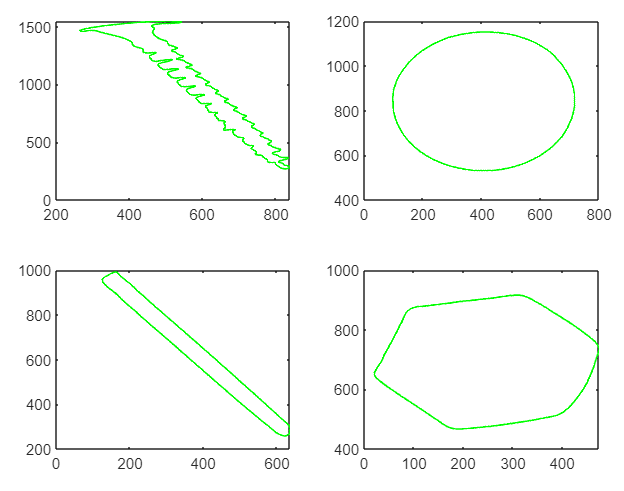

#### Cálculo de circularidad

Para calcular la circularidad de cada elemento se utilizó la función "*polyarea*"

    %% ============Circularidad=============
    area_llena = polyarea(coordenadas_perimetro(:,1), coordenadas_perimetro(:,2));
    circularidad(k) = (4 * pi * area_llena) / (perimetro(k)^2);

#### Cálculo de linealidad

Para calcular la linealidad se utilizaron las funciones "*polyfit*","*polyval*" y "*corr*"

    %% ==========Linealidad==========
    % Ajustar una línea recta a los puntos del contorno
    coefficients = polyfit(coordenadas_perimetro(:,1), coordenadas_perimetro(:,2),1); % Ajuste de mínimos cuadrados de grado 1 (línea recta)
    
    % Calcular los valores y ajustados por la línea recta
    y_fit = polyval(coefficients, coordenadas_perimetro(:,1));
    
    % Calcular el coeficiente de correlación
    linealidad(k) = corr(coordenadas_perimetro(:,2), y_fit);
end

#### Normalizado de características

Normalizado de caracteristicas: esto se realiza para que todas las caracteristicas tengan el mismo peso al momento de tomar la decisión. Luego de realizar dicha normalización, los valores de las características se guardan en la matriz "Caracteristicas".

for (k = 1:4)
    % Normalizar el vector de momentos de Hu 
    MHu_norm(k,1) = MHu(k,1) / norm(MHu(:,1));
    MHu_norm(k,2) = MHu(k,2) / norm(MHu(:,2));
    MHu_norm(k,3) = MHu(k,3) / norm(MHu(:,3));
    MHu_norm(k,4) = MHu(k,4) / norm(MHu(:,4));
    MHu_norm(k,5) = MHu(k,5) / norm(MHu(:,5));
    MHu_norm(k,6) = MHu(k,6) / norm(MHu(:,6));
    MHu_norm(k,7) = MHu(k,7) / norm(MHu(:,7));
    
    % Normalizar otras variables
    area_norm(k) = area(k) / norm(area);
    perimetro_norm(k) = perimetro(k) / norm(perimetro);
    circularidad_norm(k) = circularidad(k) / norm(circularidad);
    linealidad_norm(k) = linealidad(k) / norm(linealidad);
    Caracteristicas(k,:) = [MHu_norm(k,:),area_norm(k),perimetro_norm(k),circularidad_norm(k),linealidad_norm(k)];  %Guardado de caracteristicas en una matriz
end

#### Tabla de características

Display de caracteristicas

if plotear_todo == 1
    nombre_imagenes = {'Imagen 1','Imagen 2','Imagen 3','Imagen 4'};
    MHu1 = Caracteristicas(:,1);
    MHu2 = Caracteristicas(:,2);
    MHu3 = Caracteristicas(:,3);
    MHu4 = Caracteristicas(:,4);
    MHu5 = Caracteristicas(:,5);
    MHu6 = Caracteristicas(:,6);
    MHu7 = Caracteristicas(:,7);
    Area = Caracteristicas(:,8);
    Perimetro = Caracteristicas(:,9);
    Circularidad = Caracteristicas(:,10);
    Linealidad = Caracteristicas(:,11);
    T = table(MHu1,MHu2,MHu3,MHu4,MHu5,MHu6,MHu7,Area,Perimetro,Circularidad,Linealidad,'rowNames',nombre_imagenes);
    disp(T);
end

#### Almacenamiento en Base de datos

Si la opción elegida por el usuario fue igual a 2, entoces todos los cálculos se almacenan en la base de datos

    if (opcion == 2)
        Base_de_Datos(MHu_norm,filtro,vector_elemento,perimetro_norm,area_norm,circularidad_norm,linealidad_norm);
        Calculo_Centroides_Kmeans();

#### Ploteo de características

En caso afirmativo, se procede a graficar tres características en un diagrama tridimensional para cada entrada en la base de datos. En este gráfico se representan todas las características elegidas de la base de datos. Si se opta por "Sí" en la variable "graficar_imagen_sobre_datos", también se incluirán las características de la imagen bajo análisis en el mismo gráfico tridimensional. Por otro lado, si se selecciona "No", estas características se graficarán por separado, tal como se muestra en la figura.

Además, esas tres caracteristicas seleccionadas serán las que se utilizarán en los algoritmos Knn y Kmeans para realizar los cálculos.

    else
        X = 1;
        Y = 8;
        Z = 10;
        if plotear_todo == 1
            graficar_imagen_sobre_datos = 1;        
        
            Nombres_ejes = {'MHu1','MHu2','MHu3','MHu4','MHu5','MHu6','MHu7','Area','Perimetro','Circularidad','Linealidad'};
            
            figure;
            clf;
            xlabel(Nombres_ejes(X));
            ylabel(Nombres_ejes(Y));
            zlabel(Nombres_ejes(Z));
            grid on;
            hold on;
            load('Datos_Caracteristicas.mat');
            for (i = 1:length(tuercas_ADF_Med_Bin(:,1)))
                %MHu,area,perimetro,circularidad,linealidad
                plot3(tuercas_ADF_Med_Bin(i,X),tuercas_ADF_Med_Bin(i,Y),tuercas_ADF_Med_Bin(i,Z),'ro', 'MarkerSize', 6);
                plot3(clavos_ADF_Med_Bin(i,X),clavos_ADF_Med_Bin(i,Y),clavos_ADF_Med_Bin(i,Z),'m^', 'MarkerSize', 6);
                plot3(tornillos_ADF_Med_Bin(i,X),tornillos_ADF_Med_Bin(i,Y),tornillos_ADF_Med_Bin(i,Z),'g*', 'MarkerSize', 6);
                plot3(arandelas_ADF_Med_Bin(i,X),arandelas_ADF_Med_Bin(i,Y),arandelas_ADF_Med_Bin(i,Z),'bs', 'MarkerSize', 6);
            end
            if graficar_imagen_sobre_datos == 1
                title('Caracteristicas')
                plot3(Caracteristicas(1,X),Caracteristicas(1,Y),Caracteristicas(1,Z),'ko', 'MarkerSize', 6);
                plot3(Caracteristicas(2,X),Caracteristicas(2,Y),Caracteristicas(2,Z),'k^', 'MarkerSize', 6);
                plot3(Caracteristicas(3,X),Caracteristicas(3,Y),Caracteristicas(3,Z),'k*', 'MarkerSize', 6);
                plot3(Caracteristicas(4,X),Caracteristicas(4,Y),Caracteristicas(4,Z),'ks', 'MarkerSize', 6);
                legend('Tuercas', 'Clavos', 'Tornillos', 'Arandelas', 'Figura 1', 'Figura 2', 'Figura 3', 'Figura 4');
                view(45,45);
                hold off;
            else
                title('Caract. Base de Datos')
                legend('Tuercas', 'Clavos', 'Tornillos', 'Arandelas')
                view(45,45);
                hold off;
                figure;
                clf;
                title('Caract. imagen a analizar');
                xlabel(Nombres_ejes(X));
                ylabel(Nombres_ejes(Y));
                zlabel(Nombres_ejes(Z));
                grid on;
                hold on;
                plot3(Caracteristicas(1,X),Caracteristicas(1,Y),Caracteristicas(1,Z),'ko', 'MarkerSize', 6);
                plot3(Caracteristicas(2,X),Caracteristicas(2,Y),Caracteristicas(2,Z),'k^', 'MarkerSize', 6);
                plot3(Caracteristicas(3,X),Caracteristicas(3,Y),Caracteristicas(3,Z),'k*', 'MarkerSize', 6);
                plot3(Caracteristicas(4,X),Caracteristicas(4,Y),Caracteristicas(4,Z),'ks', 'MarkerSize', 6);
                legend('Figura 1', 'Figura 2', 'Figura 3', 'Figura 4');
                view(45,45);
                hold off;
                
            end
        end


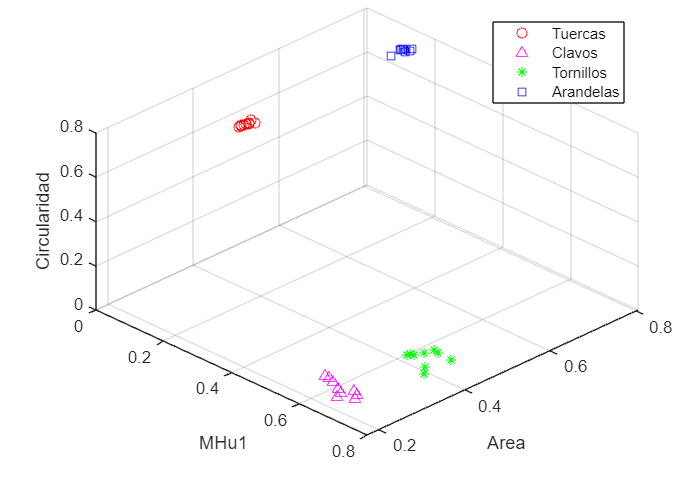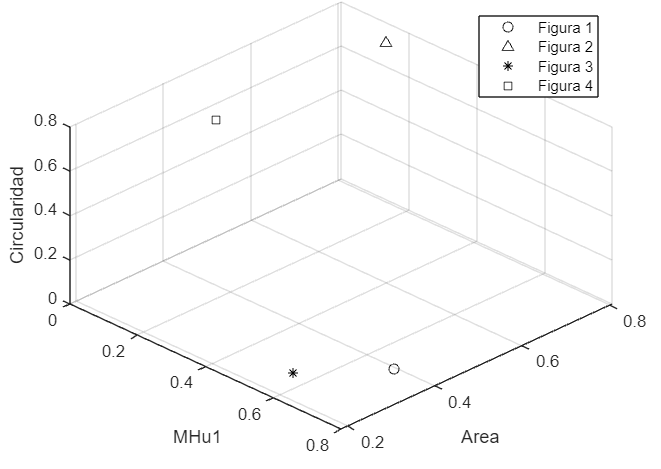

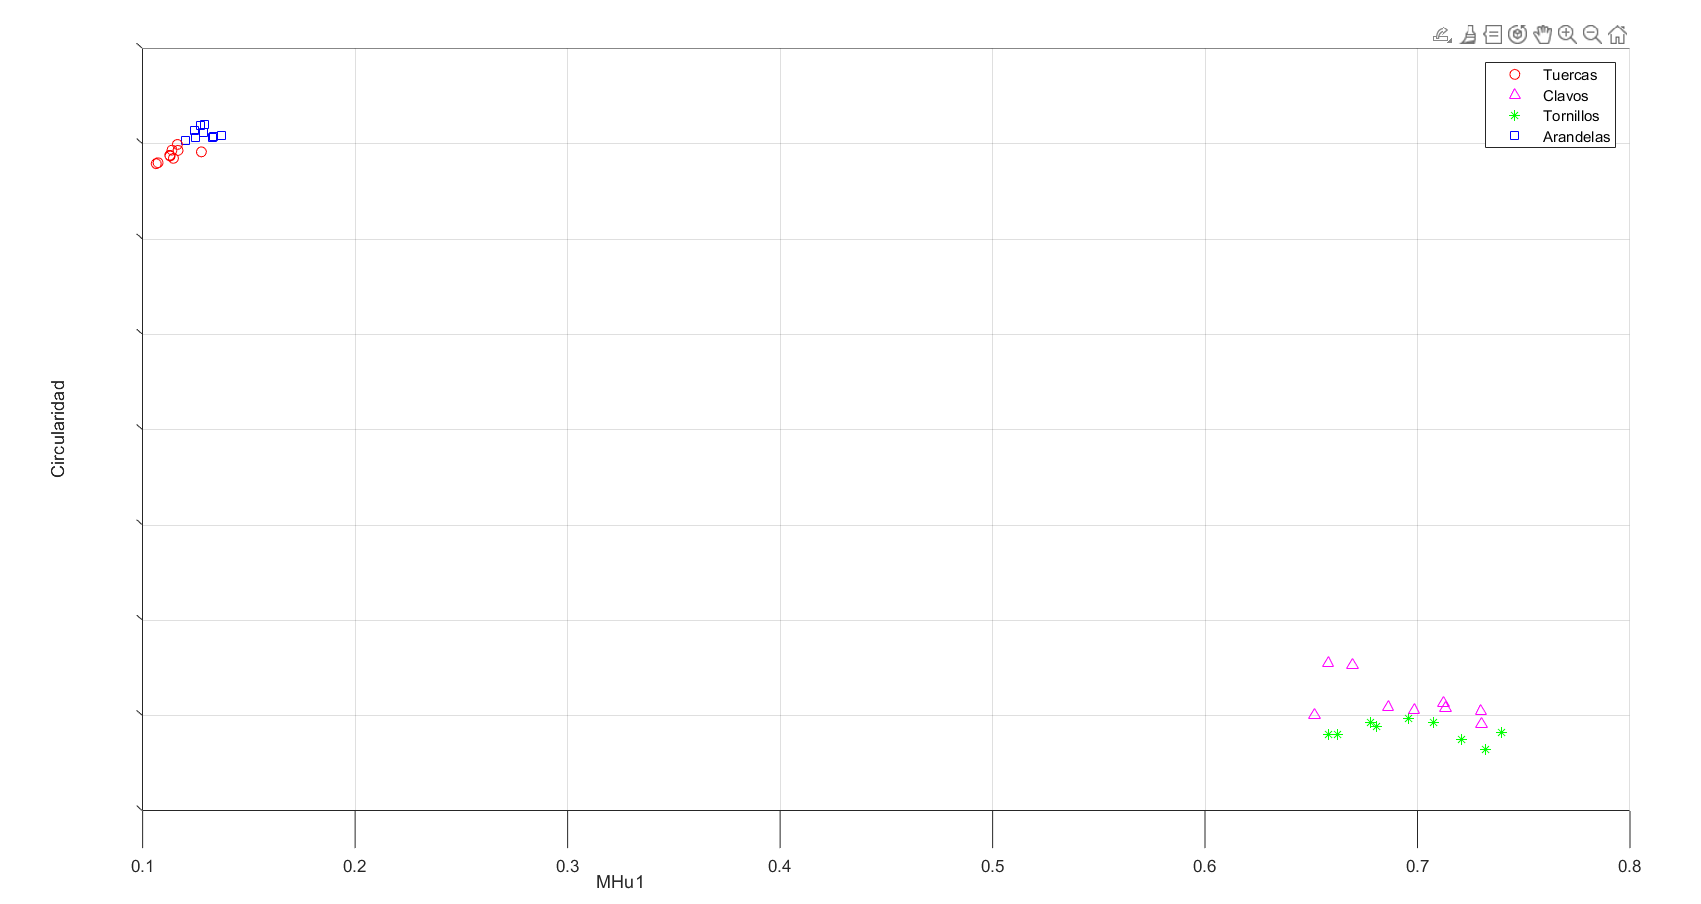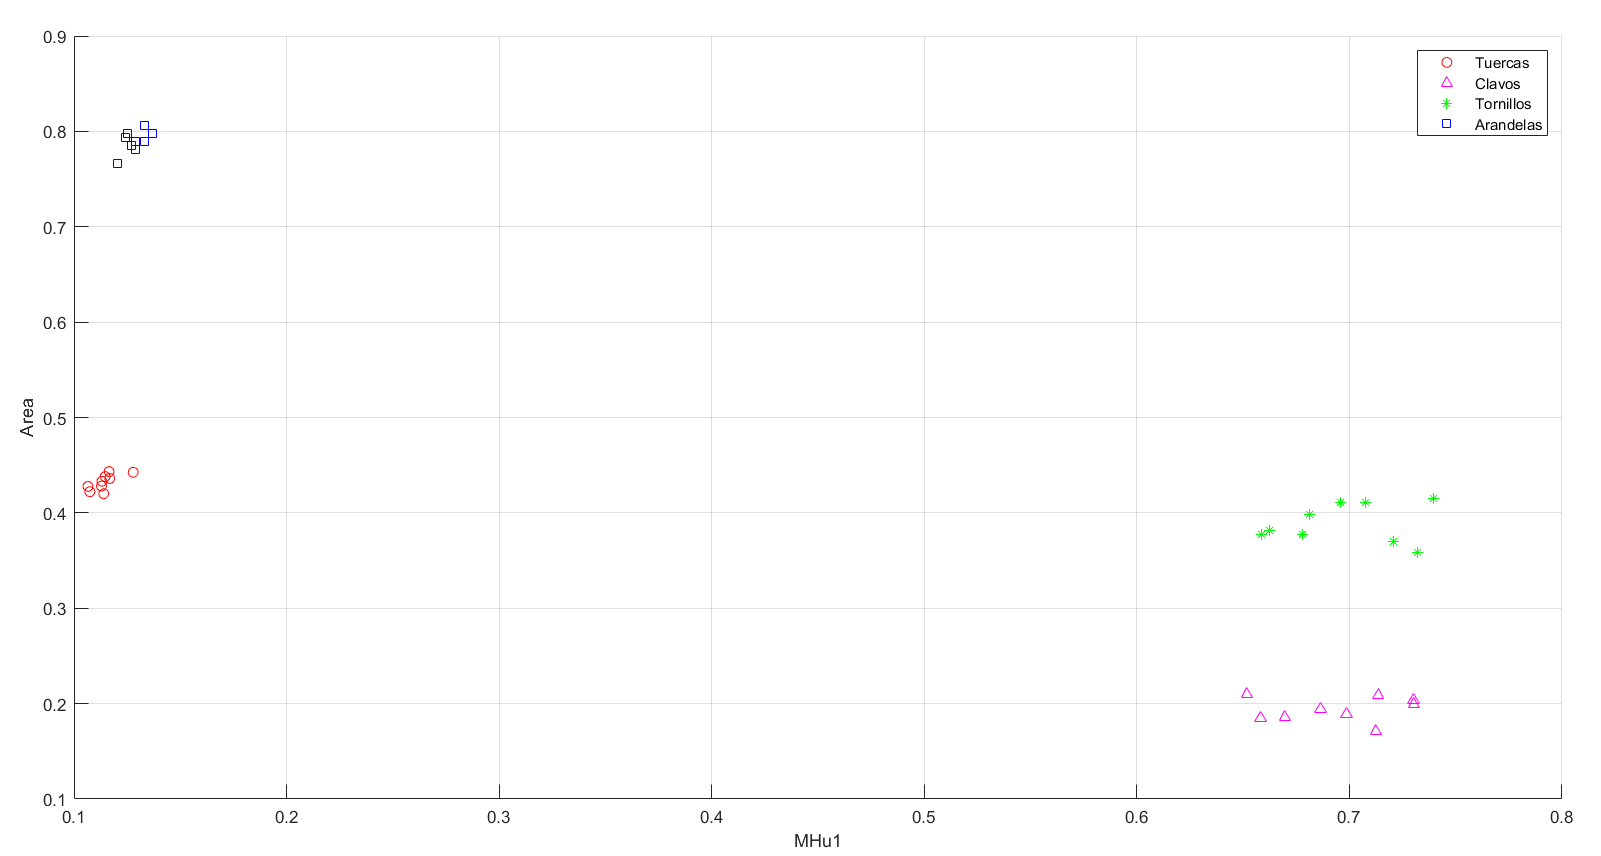

Como se pudo apreciar en las imagenes anteriores, las características de MHu1, Circularidad y Área son suficientes para diferenciar los elementos.

- MHu1: Separa bien los tornillos y clavos de las tuercas y arandelas;

- Circularidad: Separa bien los tornillos y clavos de las tuercas y arandelas y separa un poco las tuerca de las arandelas y un poco los tornillos de los clavos;

- Área: Separa muy bien las arandelas de las tuercas y los tornillos de los clavos.

#### Llamado de Knn y Kmeans

        if algoritmo == "Knn"
            Knn(Caracteristicas,filtro,X,Y,Z);
        elseif algoritmo  == "Kmeans"
            Kmeans(Caracteristicas,filtro,plotear_todo,X,Y,Z)
        end
    end
end

### ***Knn***

function Knn(Caracteristicas,filtro,X,Y,Z)
rta_knn = [];   %Almacena las respuestas de las imagenes

Se carga la base de datos

load("Datos_Caracteristicas.mat");

Constantes, donde se puede seleccionar un número impar para "knn", el cual indica la cantidad de elementos más cercanos a cada imagen según la distancia euclidiana.

[cant_datos, ~] = size(tuercas_ADF_Med_Bin);
knn = 3;

#### Distancias euclidianas

Cálculo de distancias euclidianas para el filtro seleccionado anteriormente. Se vieron buenos resultados tomando solamente MHu1, Area y Circularidad.

for(k = 1:4)
    Dist_Euclidiana = []; %Para el calculo se tiene en cuenta MomentoHu 1, Area y Circularidad
    if (filtro == 1)    %ADF
        for(i = 1:cant_datos)
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tornillos_ADF(i,X))^2+(Caracteristicas(k,Y)-tornillos_ADF(i,Y))^2+(Caracteristicas(k,Z)-tornillos_ADF(i,Z))^2),1];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-clavos_ADF(i,X))^2+(Caracteristicas(k,Y)-clavos_ADF(i,Y))^2+(Caracteristicas(k,Z)-clavos_ADF(i,Z))^2),2];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tuercas_ADF(i,X))^2+(Caracteristicas(k,Y)-tuercas_ADF(i,Y))^2+(Caracteristicas(k,Z)-tuercas_ADF(i,Z))^2),3];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-arandelas_ADF(i,X))^2+(Caracteristicas(k,Y)-arandelas_ADF(i,Y))^2+(Caracteristicas(k,Z)-arandelas_ADF(i,Z))^2),4];
        end
    elseif(filtro == 2) %PB
        for(i = 1:cant_datos)
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tornillos_PB(i,X))^2+(Caracteristicas(k,Y)-tornillos_PB(i,Y))^2+(Caracteristicas(k,Z)-tornillos_PB(i,Z))^2),1];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-clavos_PB(i,X))^2+(Caracteristicas(k,Y)-clavos_PB(i,Y))^2+(Caracteristicas(k,Z)-clavos_PB(i,Z))^2),2];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tuercas_PB(i,X))^2+(Caracteristicas(k,Y)-tuercas_PB(i,Y))^2+(Caracteristicas(k,Z)-tuercas_PB(i,Z))^2),3];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-arandelas_PB(i,X))^2+(Caracteristicas(k,Y)-arandelas_PB(i,Y))^2+(Caracteristicas(k,Z)-arandelas_PB(i,Z))^2),4];
        end
    elseif(filtro == 3) %Bin
        for(i = 1:cant_datos)
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tornillos_Bin(i,X))^2+(Caracteristicas(k,Y)-tornillos_Bin(i,Y))^2+(Caracteristicas(k,Z)-tornillos_Bin(i,Z))^2),1];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-clavos_Bin(i,X))^2+(Caracteristicas(k,Y)-clavos_Bin(i,Y))^2+(Caracteristicas(k,Z)-clavos_Bin(i,Z))^2),2];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tuercas_Bin(i,X))^2+(Caracteristicas(k,Y)-tuercas_Bin(i,Y))^2+(Caracteristicas(k,Z)-tuercas_Bin(i,Z))^2),3];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-arandelas_Bin(i,X))^2+(Caracteristicas(k,Y)-arandelas_Bin(i,Y))^2+(Caracteristicas(k,Z)-arandelas_Bin(i,Z))^2),4];
        end

    elseif(filtro == 4) %ADF+Bin
        for(i = 1:cant_datos)
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tornillos_ADF_Bin(i,X))^2+(Caracteristicas(k,Y)-tornillos_ADF_Bin(i,Y))^2+(Caracteristicas(k,Z)-tornillos_ADF_Bin(i,Z))^2),1];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-clavos_ADF_Bin(i,X))^2+(Caracteristicas(k,Y)-clavos_ADF_Bin(i,Y))^2+(Caracteristicas(k,Z)-clavos_ADF_Bin(i,Z))^2),2];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tuercas_ADF_Bin(i,X))^2+(Caracteristicas(k,Y)-tuercas_ADF_Bin(i,Y))^2+(Caracteristicas(k,Z)-tuercas_ADF_Bin(i,Z))^2),3];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-arandelas_ADF_Bin(i,X))^2+(Caracteristicas(k,Y)-arandelas_ADF_Bin(i,Y))^2+(Caracteristicas(k,Z)-arandelas_ADF_Bin(i,Z))^2),4];
        end
    elseif(filtro == 5) %PB+Bin
        for(i = 1:cant_datos)
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tornillos_PB_Bin(i,X))^2+(Caracteristicas(k,Y)-tornillos_PB_Bin(i,Y))^2+(Caracteristicas(k,Z)-tornillos_PB_Bin(i,Z))^2),1];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-clavos_PB_Bin(i,X))^2+(Caracteristicas(k,Y)-clavos_PB_Bin(i,Y))^2+(Caracteristicas(k,Z)-clavos_PB_Bin(i,Z))^2),2];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tuercas_PB_Bin(i,X))^2+(Caracteristicas(k,Y)-tuercas_PB_Bin(i,Y))^2+(Caracteristicas(k,Z)-tuercas_PB_Bin(i,Z))^2),3];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-arandelas_PB_Bin(i,X))^2+(Caracteristicas(k,Y)-arandelas_PB_Bin(i,Y))^2+(Caracteristicas(k,Z)-arandelas_PB_Bin(i,Z))^2),4];
        end
    elseif(filtro == 6) %ADF+Med+Bin
        for(i = 1:cant_datos)
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tornillos_ADF_Med_Bin(i,X))^2+(Caracteristicas(k,Y)-tornillos_ADF_Med_Bin(i,Y))^2+(Caracteristicas(k,Z)-tornillos_ADF_Med_Bin(i,Z))^2),1];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-clavos_ADF_Med_Bin(i,X))^2+(Caracteristicas(k,Y)-clavos_ADF_Med_Bin(i,Y))^2+(Caracteristicas(k,Z)-clavos_ADF_Med_Bin(i,Z))^2),2];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tuercas_ADF_Med_Bin(i,X))^2+(Caracteristicas(k,Y)-tuercas_ADF_Med_Bin(i,Y))^2+(Caracteristicas(k,Z)-tuercas_ADF_Med_Bin(i,Z))^2),3];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-arandelas_ADF_Med_Bin(i,X))^2+(Caracteristicas(k,Y)-arandelas_ADF_Med_Bin(i,Y))^2+(Caracteristicas(k,Z)-arandelas_ADF_Med_Bin(i,Z))^2),4];
        end
    elseif(filtro == 7) %PB+Med+Bin
        for(i = 1:cant_datos)
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tornillos_PB_Med_Bin(i,X))^2+(Caracteristicas(k,Y)-tornillos_PB_Med_Bin(i,Y))^2+(Caracteristicas(k,Z)-tornillos_PB_Med_Bin(i,Z))^2),1];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-clavos_PB_Med_Bin(i,X))^2+(Caracteristicas(k,Y)-clavos_PB_Med_Bin(i,Y))^2+(Caracteristicas(k,Z)-clavos_PB_Med_Bin(i,Z))^2),2];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-tuercas_PB_Med_Bin(i,X))^2+(Caracteristicas(k,Y)-tuercas_PB_Med_Bin(i,Y))^2+(Caracteristicas(k,Z)-tuercas_PB_Med_Bin(i,Z))^2),3];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-arandelas_PB_Med_Bin(i,X))^2+(Caracteristicas(k,Y)-arandelas_PB_Med_Bin(i,Y))^2+(Caracteristicas(k,Z)-arandelas_PB_Med_Bin(i,Z))^2),4];
        end
    end

#### Ordenamiento y contadores

Ordenamiento de menor a mayor de las distancias euclidianas

    [~, idx] = sort(Dist_Euclidiana(:,1));	% Ordena la matriz Dist_Euclidiana según los valores de su primera columna
    Dist_Euclidiana_ordenada = Dist_Euclidiana(idx,:);  % Utiliza los índices de ordenamiento obtenidos para reorganizar Dist_Euclidiana
    Dist_Euclidiana_ordenada = [Dist_Euclidiana_ordenada(:,1), round(Dist_Euclidiana_ordenada(:,2))];   % Realiza el redondeo de los valores de la segunda columna de Dist_Euclidiana_ordenada y los almacena junto con los valores de la primera columna en una nueva matriz

inicialización de contadores

    % disp(Dist_Euclidiana_ordenada);
    cont_tornillos = 0;
    cont_clavos = 0;
    cont_tuercas = 0;
    cont_arandelas = 0;
    cont = zeros(4,1);

Contador de los knn elmentos más cercanos

    for (i = 1:knn)
        if (Dist_Euclidiana_ordenada(i,2) == 1)
            cont_tornillos = cont_tornillos + 1;
            cont(1,1) = cont_tornillos;
        elseif(Dist_Euclidiana_ordenada(i,2) == 2)
            cont_clavos = cont_clavos + 1;
            cont(2,1) = cont_clavos;
        elseif(Dist_Euclidiana_ordenada(i,2) == 3)
            cont_tuercas = cont_tuercas + 1;
            cont(3,1) = cont_tuercas;
        elseif(Dist_Euclidiana_ordenada(i,2) == 4)
            cont_arandelas = cont_arandelas + 1;
            cont(4,1) = cont_arandelas;
        end
    end


#### Toma de decisión

    [~, posicion] = max(cont);
    if (posicion == 1)
        rta_knn = [rta_knn;"TORNILLO"];
        % disp(['La imagen Nº',num2str(k),' es un tornillo']);
    elseif (posicion == 2)
        rta_knn = [rta_knn;"CLAVO"];
        % disp(['La imagen Nº',num2str(k),' es un clavo']);
    elseif (posicion == 3)
        rta_knn = [rta_knn;"TUERCA"];
        % disp(['La imagen Nº',num2str(k),' es una tuerca']);
    elseif (posicion == 4)
        rta_knn = [rta_knn;"ARANDELA"];
        % disp(['La imagen Nº',num2str(k),' es una arandela']);
    end
end

#### Ploteo de tabla con resultados

nombre_imagenes = {'Imagen 1','Imagen 2','Imagen 3','Imagen 4'};
T = table(rta_knn,'rowNames',nombre_imagenes,'VariableNames',{'Elemento'});
disp('========== Knn ==========')
disp(T);
end

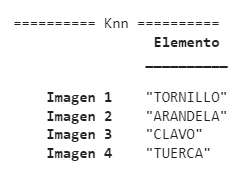

### ***Kmeans***

function Kmeans(Caracteristicas,filtro,plotear_todo,X,Y,Z)
kmeans = []; 

Se carga la base de datos

load('Datos_Centroides.mat');

#### Distancias euclidianas

Cálculo de distancia euclidiana a los centroides del filtro correspondiente

for (k = 1:4)
    Dist_Euclidiana = [];
    if (filtro == 1)
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF(1,X))^2+(Caracteristicas(k,Y)-Centroides_ADF(1,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF(1,Z))^2),1];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF(2,X))^2+(Caracteristicas(k,Y)-Centroides_ADF(2,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF(2,Z))^2),2];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF(3,X))^2+(Caracteristicas(k,Y)-Centroides_ADF(3,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF(3,Z))^2),3];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF(4,X))^2+(Caracteristicas(k,Y)-Centroides_ADF(4,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF(4,Z))^2),4];
    elseif(filtro == 2)
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB(1,X))^2+(Caracteristicas(k,Y)-Centroides_PB(1,Y))^2+(Caracteristicas(k,Z)-Centroides_PB(1,Z))^2),1];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB(2,X))^2+(Caracteristicas(k,Y)-Centroides_PB(2,Y))^2+(Caracteristicas(k,Z)-Centroides_PB(2,Z))^2),2];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB(3,X))^2+(Caracteristicas(k,Y)-Centroides_PB(3,Y))^2+(Caracteristicas(k,Z)-Centroides_PB(3,Z))^2),3];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB(4,X))^2+(Caracteristicas(k,Y)-Centroides_PB(4,Y))^2+(Caracteristicas(k,Z)-Centroides_PB(4,Z))^2),4];
    elseif(filtro == 3)
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_Bin(1,X))^2+(Caracteristicas(k,Y)-Centroides_Bin(1,Y))^2+(Caracteristicas(k,Z)-Centroides_Bin(1,Z))^2),1];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_Bin(2,X))^2+(Caracteristicas(k,Y)-Centroides_Bin(2,Y))^2+(Caracteristicas(k,Z)-Centroides_Bin(2,Z))^2),2];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_Bin(3,X))^2+(Caracteristicas(k,Y)-Centroides_Bin(3,Y))^2+(Caracteristicas(k,Z)-Centroides_Bin(3,Z))^2),3];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_Bin(4,X))^2+(Caracteristicas(k,Y)-Centroides_Bin(4,Y))^2+(Caracteristicas(k,Z)-Centroides_Bin(4,Z))^2),4];
    elseif(filtro == 4)
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF_Bin(1,X))^2+(Caracteristicas(k,Y)-Centroides_ADF_Bin(1,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF_Bin(1,Z))^2),1];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF_Bin(2,X))^2+(Caracteristicas(k,Y)-Centroides_ADF_Bin(2,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF_Bin(2,Z))^2),2];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF_Bin(3,X))^2+(Caracteristicas(k,Y)-Centroides_ADF_Bin(3,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF_Bin(3,Z))^2),3];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF_Bin(4,X))^2+(Caracteristicas(k,Y)-Centroides_ADF_Bin(4,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF_Bin(4,Z))^2),4];

    elseif(filtro == 5)
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB_Bin(1,X))^2+(Caracteristicas(k,Y)-Centroides_PB_Bin(1,Y))^2+(Caracteristicas(k,Z)-Centroides_PB_Bin(1,Z))^2),1];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB_Bin(2,X))^2+(Caracteristicas(k,Y)-Centroides_PB_Bin(2,Y))^2+(Caracteristicas(k,Z)-Centroides_PB_Bin(2,Z))^2),2];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB_Bin(3,X))^2+(Caracteristicas(k,Y)-Centroides_PB_Bin(3,Y))^2+(Caracteristicas(k,Z)-Centroides_PB_Bin(3,Z))^2),3];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB_Bin(4,X))^2+(Caracteristicas(k,Y)-Centroides_PB_Bin(4,Y))^2+(Caracteristicas(k,Z)-Centroides_PB_Bin(4,Z))^2),4];

    elseif(filtro == 6)
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF_Med_Bin(1,X))^2+(Caracteristicas(k,Y)-Centroides_ADF_Med_Bin(1,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF_Med_Bin(1,Z))^2),1];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF_Med_Bin(2,X))^2+(Caracteristicas(k,Y)-Centroides_ADF_Med_Bin(2,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF_Med_Bin(2,Z))^2),2];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF_Med_Bin(3,X))^2+(Caracteristicas(k,Y)-Centroides_ADF_Med_Bin(3,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF_Med_Bin(3,Z))^2),3];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_ADF_Med_Bin(4,X))^2+(Caracteristicas(k,Y)-Centroides_ADF_Med_Bin(4,Y))^2+(Caracteristicas(k,Z)-Centroides_ADF_Med_Bin(4,Z))^2),4];

    elseif(filtro == 7)
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB_Med_Bin(1,X))^2+(Caracteristicas(k,Y)-Centroides_PB_Med_Bin(1,Y))^2+(Caracteristicas(k,Z)-Centroides_PB_Med_Bin(1,Z))^2),1];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB_Med_Bin(2,X))^2+(Caracteristicas(k,Y)-Centroides_PB_Med_Bin(2,Y))^2+(Caracteristicas(k,Z)-Centroides_PB_Med_Bin(2,Z))^2),2];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB_Med_Bin(3,X))^2+(Caracteristicas(k,Y)-Centroides_PB_Med_Bin(3,Y))^2+(Caracteristicas(k,Z)-Centroides_PB_Med_Bin(3,Z))^2),3];
        Dist_Euclidiana = [Dist_Euclidiana ; sqrt((Caracteristicas(k,X)-Centroides_PB_Med_Bin(4,X))^2+(Caracteristicas(k,Y)-Centroides_PB_Med_Bin(4,Y))^2+(Caracteristicas(k,Z)-Centroides_PB_Med_Bin(4,Z))^2),4];
    end

#### Ordenamiento

Ordenamiento de menor a mayor entre las distancias

    [~, idx] = sort(Dist_Euclidiana(:,1));	% Ordena la matriz Dist_Euclidiana según los valores de su primera columna
    Dist_Euclidiana_ordenada = Dist_Euclidiana(idx,:);  % Utiliza los índices de ordenamiento obtenidos para reorganizar Dist_Euclidiana
    Dist_Euclidiana_ordenada = [Dist_Euclidiana_ordenada(:,1), round(Dist_Euclidiana_ordenada(:,2))];   % Realiza el redondeo de los valores de la segunda columna de Dist_Euclidiana_ordenada y los almacena junto con los valores de la primera columna en una nueva matriz

#### Toma de decisión

Se toma la decisión en base al centroide más cercano

    if (Dist_Euclidiana_ordenada(1,2) == 1)
        kmeans = [kmeans;"TORNILLO"];
        % disp(['La imagen Nº',num2str(k),' es un tornillo']);
    elseif (Dist_Euclidiana_ordenada(1,2) == 2)
        kmeans = [kmeans;"CLAVO"];
        % disp(['La imagen Nº',num2str(k),' es un clavo']);
    elseif (Dist_Euclidiana_ordenada(1,2) == 3)
        kmeans = [kmeans;"TUERCA"];
        % disp(['La imagen Nº',num2str(k),' es una tuerca']);
    elseif (Dist_Euclidiana_ordenada(1,2) == 4)
        kmeans = [kmeans;"ARANDELA"];
        % disp(['La imagen Nº',num2str(k),' es una arandela']);
    end
end

Si quiero graficar los clusters


if plotear_todo == 1
    load("Datos_Caracteristicas.mat");
    PB_Med_Bin = [tornillos_PB_Med_Bin(:,:);clavos_PB_Med_Bin(:,:);tuercas_PB_Med_Bin(:,:);arandelas_PB_Med_Bin(:,:)];
    if(filtro == 7)
        figure;
        clf;
        title('Clusters');
        Nombres_ejes = {'MHu1','MHu2','MHu3','MHu4','MHu5','MHu6','MHu7','Area','Perimetro','Circularidad','Linealidad'};
        xlabel(Nombres_ejes(X));
        ylabel(Nombres_ejes(Y));
        zlabel(Nombres_ejes(Z));
        view(45,45);
        grid on;
        hold on;
        for (k=1:length(PB_Med_Bin(:,1)))
            Dist_Euclidiana = [];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((PB_Med_Bin(k,X)-Centroides_PB_Med_Bin(1,X))^2+(PB_Med_Bin(k,Y)-Centroides_PB_Med_Bin(1,Y))^2+(PB_Med_Bin(k,Z)-Centroides_PB_Med_Bin(1,Z))^2),1];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((PB_Med_Bin(k,X)-Centroides_PB_Med_Bin(2,X))^2+(PB_Med_Bin(k,Y)-Centroides_PB_Med_Bin(2,Y))^2+(PB_Med_Bin(k,Z)-Centroides_PB_Med_Bin(2,Z))^2),2];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((PB_Med_Bin(k,X)-Centroides_PB_Med_Bin(3,X))^2+(PB_Med_Bin(k,Y)-Centroides_PB_Med_Bin(3,Y))^2+(PB_Med_Bin(k,Z)-Centroides_PB_Med_Bin(3,Z))^2),3];
            Dist_Euclidiana = [Dist_Euclidiana ; sqrt((PB_Med_Bin(k,X)-Centroides_PB_Med_Bin(4,X))^2+(PB_Med_Bin(k,Y)-Centroides_PB_Med_Bin(4,Y))^2+(PB_Med_Bin(k,Z)-Centroides_PB_Med_Bin(4,Z))^2),4];
            
            [~, idx] = sort(Dist_Euclidiana(:,1));	% Ordena la matriz Dist_Euclidiana según los valores de su primera columna
            Dist_Euclidiana_ordenada = Dist_Euclidiana(idx,:);  % Utiliza los índices de ordenamiento obtenidos para reorganizar Dist_Euclidiana
            Dist_Euclidiana_ordenada = [Dist_Euclidiana_ordenada(:,1), round(Dist_Euclidiana_ordenada(:,2))];   % Realiza el redondeo de los valores de la segunda columna de Dist_Euclidiana_ordenada y los almacena junto con los valores de la primera columna en una nueva matriz
            
            if (Dist_Euclidiana_ordenada(1,2) == 1)
                 plot3(PB_Med_Bin(k,X),PB_Med_Bin(k,Y),PB_Med_Bin(k,Z),'ro', 'MarkerSize', 6);
            elseif (Dist_Euclidiana_ordenada(1,2) == 2)
                plot3(PB_Med_Bin(k,X),PB_Med_Bin(k,Y),PB_Med_Bin(k,Z),'m^', 'MarkerSize', 6);
            elseif (Dist_Euclidiana_ordenada(1,2) == 3)
                plot3(PB_Med_Bin(k,X),PB_Med_Bin(k,Y),PB_Med_Bin(k,Z),'g*', 'MarkerSize', 6);
            elseif (Dist_Euclidiana_ordenada(1,2) == 4)
                plot3(PB_Med_Bin(k,X),PB_Med_Bin(k,Y),PB_Med_Bin(k,Z),'bs', 'MarkerSize', 6);
            end
        end
    end
    hold off;
end

#### Ploteo de tabla con resultados

nombre_imagenes = {'Imagen 1','Imagen 2','Imagen 3','Imagen 4'};
T = table(kmeans,'rowNames',nombre_imagenes,'VariableNames',{'Elemento'});
disp('========== Kmeans ==========')
disp(T);
end

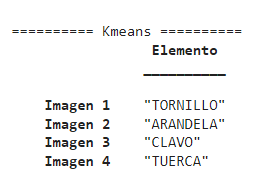

### *Comparacion filtros*

Esta función solo sirve cuando el usuario selecciona la opcion "Comparar_Filtros", el cual vendrá directo a esta función que se encarga de filtrar la imagen de diferentes formas para que el usuario pueda ver como varia uno con otro.

function Comparacion_filtros(imagen,cte_mascara,umbral,m,n)

mascara = cte_mascara*[1,1,1;1,1,1;1,1,1];

%% Imagen original
figure;
subplot(1,8,1);
imshow(imagen), title('Imagen Original'); %Imprimo imagen

matrizR = imagen(:,:,1); %matrices Red, Green, Blue
matrizG = imagen(:,:,2);
matrizB = imagen(:,:,3);

%% ========== Filtro Anisotropico ============

imagen_ADF(:,:,1)=imdiffusefilt(imagen(:,:,1));
imagen_ADF(:,:,2)=imdiffusefilt(imagen(:,:,2));
imagen_ADF(:,:,3)=imdiffusefilt(imagen(:,:,3));

subplot(1,8,2);
imshow(imagen_ADF), title('ADF');

%% ========= Filtro Pasa Bajos ============

imagen_PB(:,:,1) = filter2(mascara, matrizR);  %FiltroPasaBajo
imagen_PB(:,:,2) = filter2(mascara, matrizG);
imagen_PB(:,:,3) = filter2(mascara, matrizB);

imagen_PB = uint8(imagen_PB);   
subplot(1,8,3);
imshow(imagen_PB), title('Pasa Bajos');


%% ===============Binarizacion===============
imagen_gris = rgb2gray(imagen); %Imagen en escala de grises
imagen_binarizada = im2bw(imagen_gris, umbral);

subplot(1,8,4);
imshow(imagen_binarizada), title('Binarizado');

%% ============ Filtro ADF + Bin ============

imagen_gris_ADF = rgb2gray(imagen_ADF);
imagen_binarizada_ADF = im2bw(imagen_gris_ADF, umbral);

subplot(1,8,5);
imshow(imagen_binarizada_ADF), title('ADF + Bin');


%% ============Filtro PB + Bin ============
imagen_gris_PB = rgb2gray(imagen_PB);
imagen_binarizada_PB = im2bw(imagen_gris_PB, umbral);

subplot(1,8,6);
imshow(imagen_binarizada_PB), title('PB + Bin');

%% ============Filtro ADF + Mediana +  Bin ============  Parece que es por aca la cosa
imagen_mediana_ADF = medfilt2(imagen_gris_ADF, [m n]);  %Filtro mediana para eliminar sal y pimienta
imagen_bin_med_ADF = im2bw(imagen_mediana_ADF, umbral); %Binarizacion

subplot(1,8,7);
imshow(imagen_bin_med_ADF), title('ADF + Med + Bin'); 
%% ========== Filtro PB + Mediana + Bin ==============
imagen_mediana_PB = medfilt2(imagen_gris_PB, [m n]);
imagen_bin_med_PB = im2bw(imagen_mediana_PB, umbral);

subplot(1,8,8);
imshow(imagen_bin_med_PB), title('PB + Mediana + Bin');

% figure;
% imshow(imagen_bin_med_ADF), title('ADF + Med + Bin'); 
% figure;
% imshow(imagen_bin_med_PB), title('PB + Med + Bin'); 
end

A continuacion se muestra la comparación entre los diferentes filtros.

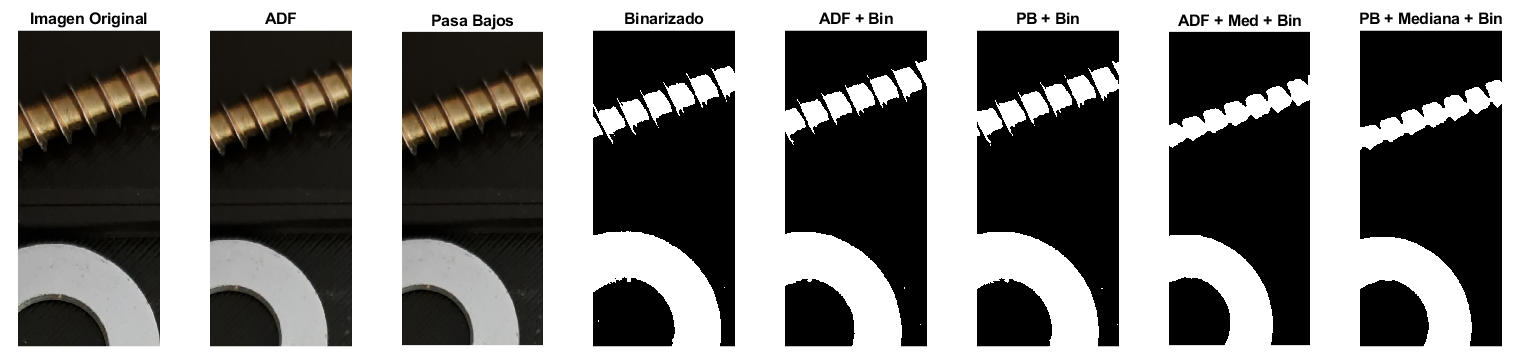

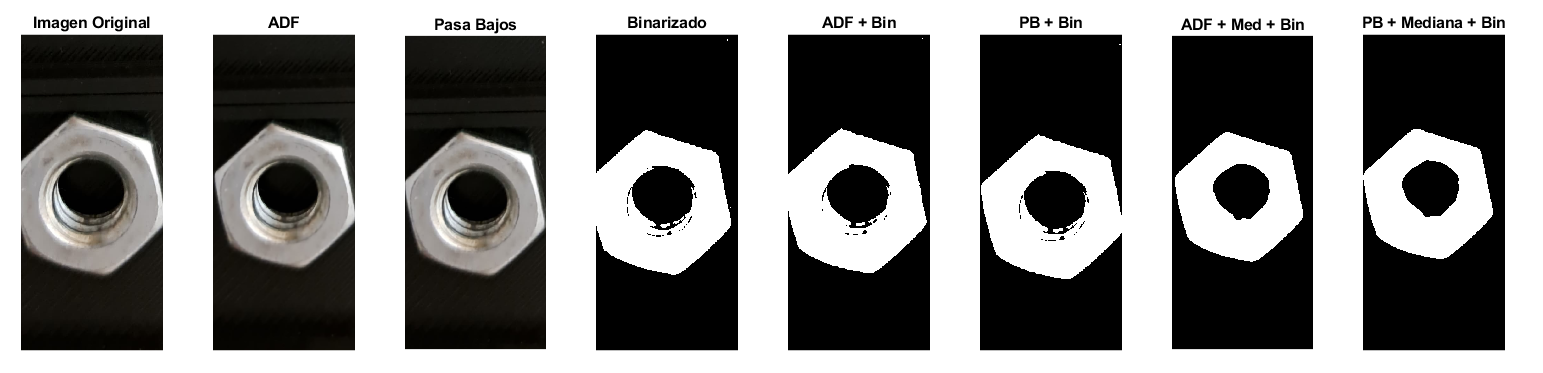

Los filtros utilizados sirven para:

- **Filtro Anisotrópico (ADF):** se utiliza principalmente para suavizar imágenes mientras se conservan bordes y detalles importantes

- **Filtro Pasa Bajos (PB): **se utiliza para suavizar una imagen al reducir las altas frecuencias. En el procesamiento de imágenes, las altas frecuencias representan los cambios rápidos de intensidad, que a menudo corresponden al ruido o detalles no deseados.

- **Binarización: **Una vez hecha la transformacion de imagen RGB a imagen en escala de grises, se aplica este filtro y segun sea su valor numerico de cada pixel, se convertirá en 1 o 0. Esto facilita los calculos de las caracteristicas de la imagen

- **Mediana: **reemplaza el valor de cada píxel en la imagen con la mediana de los valores de intensidad en su vecindad. Esto es eficaz para eliminar el ruido impulsivo o "sal y pimienta".

### ***Cálculo de centroides***

Esta función se utiliza cuando se quiere agregar una imagen a la base de datos, o sea, cuando el usuario selecciona la opcion "Entrenar_IA". Cada vez que entra a esta función, recalcula los centroides con la nueva información para luego poder utilizarlos al momento de utilizar el algoritmo Kmeans. De esta forma se evita recalcular los centroides cada vez que se quiere analizar una imagen, logrando asi optimizar el código.

function Calculo_Centroides_Kmeans()
clc;
clear;

Carga de base de datos

load('Datos_Caracteristicas.mat');

Constantes, el cual se puede modificar la cantidad de iteraciones para clusterizar.

iteraciones = 10; %Valor optimo 10
cant_cluster = 4;
centroide = zeros(4,1);
%ADF = [tornillos_ADF(:,:);clavos_ADF(:,:);tuercas_ADF(:,:);arandelas_ADF(:,:)];

Creo matrices generales con toda la base de datos existente

ADF_Bin = [tornillos_ADF_Bin(:,:);clavos_ADF_Bin(:,:);tuercas_ADF_Bin(:,:);arandelas_ADF_Bin(:,:)];
ADF_Med_Bin = [tornillos_ADF_Med_Bin(:,:);clavos_ADF_Med_Bin(:,:);tuercas_ADF_Med_Bin(:,:);arandelas_ADF_Med_Bin(:,:)];
Bin = [tornillos_Bin(:,:);clavos_Bin(:,:);tuercas_Bin(:,:);arandelas_Bin(:,:)];
PB = [tornillos_PB(:,:);clavos_PB(:,:);tuercas_PB(:,:);arandelas_PB(:,:)];
PB_Bin = [tornillos_PB_Bin(:,:);clavos_PB_Bin(:,:);tuercas_PB_Bin(:,:);arandelas_PB_Bin(:,:)];
PB_Med_Bin = [tornillos_PB_Med_Bin(:,:);clavos_PB_Med_Bin(:,:);tuercas_PB_Med_Bin(:,:);arandelas_PB_Med_Bin(:,:)];

Vectores que almacenarán los centroides para cada filtro

dist_euc = zeros(1,cant_cluster);
Centroides_ADF = [];
Centroides_ADF_Bin = [];
Centroides_ADF_Med_Bin = [];
Centroides_Bin = [];
Centroides_PB = [];
Centroides_PB_Bin = [];
Centroides_PB_Med_Bin = [];

#### Cálculo de centroides 

La explicación más completa se encuentra en el calculo de los centroides para Pasa Bajo + Mediana + Binarizacion, ya que los procedimientos son los mismos para cada filtro aplicado

%% =========== Centroides ADF =============

% for (j = 1:length(tornillos_ADF(1,:)))
%     centroide(1) = tornillos_ADF(1,j); 
%     centroide(2) = clavos_ADF(1,j);
%     centroide(3) = tuercas_ADF(1,j);
%     centroide(4) = arandelas_ADF(1,j);
%     for (it = 1:iteraciones)
%         Datos = ADF(:,j);
%         Datos_Clasif_1 = [];
%         Datos_Clasif_2 = [];
%         Datos_Clasif_3 = [];
%         Datos_Clasif_4 = [];
% 
%         for(i = 1:length(Datos(:,1)))
%             dist_euc(1) = sqrt(abs(Datos(i,1)^2-centroide(1)^2));
%             dist_euc(2) = sqrt(abs(Datos(i,1)^2-centroide(2)^2));
%             dist_euc(3) = sqrt(abs(Datos(i,1)^2-centroide(3)^2));
%             dist_euc(4) = sqrt(abs(Datos(i,1)^2-centroide(4)^2));
%             [~, posicion] = min(dist_euc);
% 
%             if (posicion == 1)  
%                 Datos_Clasif_1 = [Datos_Clasif_1,Datos(i,1)];
%             elseif (posicion == 2)
%                 Datos_Clasif_2 = [Datos_Clasif_2,Datos(i,1)];
%             elseif (posicion == 3)
%                 Datos_Clasif_3 = [Datos_Clasif_3,Datos(i,1)];
%             elseif (posicion == 4)
%                 Datos_Clasif_4 = [Datos_Clasif_4,Datos(i,1)];
%             end
%         end
% 
%             centroide(1) = mean(Datos_Clasif_1);
%             centroide(2) = mean(Datos_Clasif_2);
%             centroide(3) = mean(Datos_Clasif_3);
%             centroide(4) = mean(Datos_Clasif_4);
%     end
% 
% Centroides_ADF = [Centroides_ADF, centroide];
% end

%% =========== Centroides ADF_Bin ===============

for (j = 1:length(tornillos_ADF_Bin(1,:)))
    centroide(1) = tornillos_ADF_Bin(1,j);
    centroide(2) = clavos_ADF_Bin(1,j);
    centroide(3) = tuercas_ADF_Bin(1,j);
    centroide(4) = arandelas_ADF_Bin(1,j);
    for (it = 1:iteraciones)
        Datos = ADF_Bin(:,j);
        Datos_Clasif_1 = [];
        Datos_Clasif_2 = [];
        Datos_Clasif_3 = [];
        Datos_Clasif_4 = [];

        for(i = 1:length(Datos(:,1)))
            dist_euc(1) = sqrt(abs(Datos(i,1)^2-centroide(1)^2));
            dist_euc(2) = sqrt(abs(Datos(i,1)^2-centroide(2)^2));
            dist_euc(3) = sqrt(abs(Datos(i,1)^2-centroide(3)^2));
            dist_euc(4) = sqrt(abs(Datos(i,1)^2-centroide(4)^2));
            [~, posicion] = min(dist_euc);

            if (posicion == 1)  
                Datos_Clasif_1 = [Datos_Clasif_1,Datos(i,1)];
            elseif (posicion == 2)
                Datos_Clasif_2 = [Datos_Clasif_2,Datos(i,1)];
            elseif (posicion == 3)
                Datos_Clasif_3 = [Datos_Clasif_3,Datos(i,1)];
            elseif (posicion == 4)
                Datos_Clasif_4 = [Datos_Clasif_4,Datos(i,1)];
            end
        end
 
            centroide(1) = mean(Datos_Clasif_1);
            centroide(2) = mean(Datos_Clasif_2);
            centroide(3) = mean(Datos_Clasif_3);
            centroide(4) = mean(Datos_Clasif_4);
    end

Centroides_ADF_Bin = [Centroides_ADF_Bin, centroide];
end

%% ========== Centroides ADF_MED_BIN ============
for (j = 1:length(tornillos_ADF_Med_Bin(1,:)))
    centroide(1) = tornillos_ADF_Med_Bin(1,j);
    centroide(2) = clavos_ADF_Med_Bin(1,j);
    centroide(3) = tuercas_ADF_Med_Bin(1,j);
    centroide(4) = arandelas_ADF_Med_Bin(1,j);
    for (it = 1:iteraciones)
        Datos = ADF_Med_Bin(:,j);
        Datos_Clasif_1 = [];
        Datos_Clasif_2 = [];
        Datos_Clasif_3 = [];
        Datos_Clasif_4 = [];

        for(i = 1:length(Datos(:,1)))
            dist_euc(1) = sqrt(abs(Datos(i,1)^2-centroide(1)^2));
            dist_euc(2) = sqrt(abs(Datos(i,1)^2-centroide(2)^2));
            dist_euc(3) = sqrt(abs(Datos(i,1)^2-centroide(3)^2));
            dist_euc(4) = sqrt(abs(Datos(i,1)^2-centroide(4)^2));
            [~, posicion] = min(dist_euc);

            if (posicion == 1)  
                Datos_Clasif_1 = [Datos_Clasif_1,Datos(i,1)];
            elseif (posicion == 2)
                Datos_Clasif_2 = [Datos_Clasif_2,Datos(i,1)];
            elseif (posicion == 3)
                Datos_Clasif_3 = [Datos_Clasif_3,Datos(i,1)];
            elseif (posicion == 4)
                Datos_Clasif_4 = [Datos_Clasif_4,Datos(i,1)];
            end
        end
 
            centroide(1) = mean(Datos_Clasif_1);
            centroide(2) = mean(Datos_Clasif_2);
            centroide(3) = mean(Datos_Clasif_3);
            centroide(4) = mean(Datos_Clasif_4);
    end

Centroides_ADF_Med_Bin = [Centroides_ADF_Med_Bin, centroide];
end

%% =========== Centroides Bin ==============

for (j = 1:length(tornillos_Bin(1,:)))
    centroide(1) = tornillos_Bin(1,j);
    centroide(2) = clavos_Bin(1,j);
    centroide(3) = tuercas_Bin(1,j);
    centroide(4) = arandelas_Bin(1,j);
    for (it = 1:iteraciones)
        Datos = Bin(:,j);
        Datos_Clasif_1 = [];
        Datos_Clasif_2 = [];
        Datos_Clasif_3 = [];
        Datos_Clasif_4 = [];

        for(i = 1:length(Datos(:,1)))
            dist_euc(1) = sqrt(abs(Datos(i,1)^2-centroide(1)^2));
            dist_euc(2) = sqrt(abs(Datos(i,1)^2-centroide(2)^2));
            dist_euc(3) = sqrt(abs(Datos(i,1)^2-centroide(3)^2));
            dist_euc(4) = sqrt(abs(Datos(i,1)^2-centroide(4)^2));
            [~, posicion] = min(dist_euc);

            if (posicion == 1)  
                Datos_Clasif_1 = [Datos_Clasif_1,Datos(i,1)];
            elseif (posicion == 2)
                Datos_Clasif_2 = [Datos_Clasif_2,Datos(i,1)];
            elseif (posicion == 3)
                Datos_Clasif_3 = [Datos_Clasif_3,Datos(i,1)];
            elseif (posicion == 4)
                Datos_Clasif_4 = [Datos_Clasif_4,Datos(i,1)];
            end
        end
 
            centroide(1) = mean(Datos_Clasif_1);
            centroide(2) = mean(Datos_Clasif_2);
            centroide(3) = mean(Datos_Clasif_3);
            centroide(4) = mean(Datos_Clasif_4);
    end

Centroides_Bin = [Centroides_Bin, centroide];
end
%% =========== Centroides PB ===============

for (j = 1:length(tornillos_PB(1,:)))
    centroide(1) = tornillos_PB(1,j);
    centroide(2) = clavos_PB(1,j);
    centroide(3) = tuercas_PB(1,j);
    centroide(4) = arandelas_PB(1,j);
    for (it = 1:iteraciones)
        Datos = PB(:,j);
        Datos_Clasif_1 = [];
        Datos_Clasif_2 = [];
        Datos_Clasif_3 = [];
        Datos_Clasif_4 = [];

        for(i = 1:length(Datos(:,1)))
            dist_euc(1) = sqrt(abs(Datos(i,1)^2-centroide(1)^2));
            dist_euc(2) = sqrt(abs(Datos(i,1)^2-centroide(2)^2));
            dist_euc(3) = sqrt(abs(Datos(i,1)^2-centroide(3)^2));
            dist_euc(4) = sqrt(abs(Datos(i,1)^2-centroide(4)^2));
            [~, posicion] = min(dist_euc);

            if (posicion == 1)  
                Datos_Clasif_1 = [Datos_Clasif_1,Datos(i,1)];
            elseif (posicion == 2)
                Datos_Clasif_2 = [Datos_Clasif_2,Datos(i,1)];
            elseif (posicion == 3)
                Datos_Clasif_3 = [Datos_Clasif_3,Datos(i,1)];
            elseif (posicion == 4)
                Datos_Clasif_4 = [Datos_Clasif_4,Datos(i,1)];
            end
        end
 
            centroide(1) = mean(Datos_Clasif_1);
            centroide(2) = mean(Datos_Clasif_2);
            centroide(3) = mean(Datos_Clasif_3);
            centroide(4) = mean(Datos_Clasif_4);
    end

Centroides_PB = [Centroides_PB, centroide];
end
%% =========== Centroides PB_Bin ===============

for (j = 1:length(tornillos_PB_Bin(1,:)))
    centroide(1) = tornillos_PB_Bin(1,j);
    centroide(2) = clavos_PB_Bin(1,j);
    centroide(3) = tuercas_PB_Bin(1,j);
    centroide(4) = arandelas_PB_Bin(1,j);
    for (it = 1:iteraciones)
        Datos = PB_Bin(:,j);
        Datos_Clasif_1 = [];
        Datos_Clasif_2 = [];
        Datos_Clasif_3 = [];
        Datos_Clasif_4 = [];

        for(i = 1:length(Datos(:,1)))
            dist_euc(1) = sqrt(abs(Datos(i,1)^2-centroide(1)^2));
            dist_euc(2) = sqrt(abs(Datos(i,1)^2-centroide(2)^2));
            dist_euc(3) = sqrt(abs(Datos(i,1)^2-centroide(3)^2));
            dist_euc(4) = sqrt(abs(Datos(i,1)^2-centroide(4)^2));
            [~, posicion] = min(dist_euc);

            if (posicion == 1)  
                Datos_Clasif_1 = [Datos_Clasif_1,Datos(i,1)];
            elseif (posicion == 2)
                Datos_Clasif_2 = [Datos_Clasif_2,Datos(i,1)];
            elseif (posicion == 3)
                Datos_Clasif_3 = [Datos_Clasif_3,Datos(i,1)];
            elseif (posicion == 4)
                Datos_Clasif_4 = [Datos_Clasif_4,Datos(i,1)];
            end
        end
 
            centroide(1) = mean(Datos_Clasif_1);
            centroide(2) = mean(Datos_Clasif_2);
            centroide(3) = mean(Datos_Clasif_3);
            centroide(4) = mean(Datos_Clasif_4);
    end

Centroides_PB_Bin = [Centroides_PB_Bin, centroide];
end


Se calcula centroide para cada caracteristica. Para lograr esto, se ingresó como primeros centroides los valores de la primer imagen de la base de datos. Esto no es lo correcto ya que el algoritmo pasa a ser supervisado, sin embargo la convergencia es mucho mas rápida por lo que se necesitan menos iteraciones y logra optimizar el código.

%% =========== Centroides PB_Med_Bin ===============
for (j = 1:length(tornillos_PB_Med_Bin(1,:)))
    centroide(1) = tornillos_PB_Med_Bin(1,j);   %Se asignan centroides iniciales
    centroide(2) = clavos_PB_Med_Bin(1,j);
    centroide(3) = tuercas_PB_Med_Bin(1,j);
    centroide(4) = arandelas_PB_Med_Bin(1,j);
    for (it = 1:iteraciones)
        Datos = PB_Med_Bin(:,j);    %Todos los datos de todas las imagenes para la caracteristica y filtro correspondiente
        Datos_Clasif_1 = [];    %Vectores para almacenar distancias
        Datos_Clasif_2 = [];
        Datos_Clasif_3 = [];
        Datos_Clasif_4 = [];

        for(i = 1:length(Datos(:,1)))
            dist_euc(1) = sqrt(abs(Datos(i,1)^2-centroide(1)^2));   %Calculo de distancia a cada centroide
            dist_euc(2) = sqrt(abs(Datos(i,1)^2-centroide(2)^2));
            dist_euc(3) = sqrt(abs(Datos(i,1)^2-centroide(3)^2));
            dist_euc(4) = sqrt(abs(Datos(i,1)^2-centroide(4)^2));
            [~, posicion] = min(dist_euc);  %

            if (posicion == 1)  
                Datos_Clasif_1 = [Datos_Clasif_1,Datos(i,1)];
            elseif (posicion == 2)
                Datos_Clasif_2 = [Datos_Clasif_2,Datos(i,1)];
            elseif (posicion == 3)
                Datos_Clasif_3 = [Datos_Clasif_3,Datos(i,1)];
            elseif (posicion == 4)
                Datos_Clasif_4 = [Datos_Clasif_4,Datos(i,1)];
            end
        end
        centroide(1) = mean(Datos_Clasif_1);
        centroide(2) = mean(Datos_Clasif_2);
        centroide(3) = mean(Datos_Clasif_3);
        centroide(4) = mean(Datos_Clasif_4);

    end

Centroides_PB_Med_Bin = [Centroides_PB_Med_Bin, centroide];
end

% save('Datos_Centroides.mat', 'Centroides_ADF','Centroides_ADF_Bin','Centroides_ADF_Med_Bin','Centroides_Bin','Centroides_PB','Centroides_PB_Bin','Centroides_PB_Med_Bin');
end
%% Cluster

### ***Base de Datos***

Esta función es la encargada de almacenar toda la información según la selección previa del usuario.

function Base_de_Datos(MHu,filtro,vector_elemento,perimetro,area,circularidad,linealidad)

load("Datos_Caracteristicas.mat");
    for (i = 1:4)   %Recorre el vector_elemento para saber a que elemento se le asignan los resultados de las caracteristicas
        if (vector_elemento(i) == 1)
            tornillo = MHu(i,:);
            perimetro_tornillo = perimetro(i); 
            area_tornillo = area(i);
            circularidad_tornillo = circularidad(i);
            linealidad_tornillo = linealidad(i);
        elseif(vector_elemento(i) == 2)
            clavo = MHu(i,:);
            perimetro_clavo = perimetro(i);
            area_clavo = area(i);
            circularidad_clavo = circularidad(i);
            linealidad_clavo = linealidad(i);
        elseif(vector_elemento(i) == 3)
            tuerca = MHu(i,:);
            perimetro_tuerca = perimetro(i);
            area_tuerca = area(i);
            circularidad_tuerca = circularidad(i);
            linealidad_tuerca = linealidad(i);
        elseif(vector_elemento(i) == 4)
            arandela = MHu(i,:);
            perimetro_arandela = perimetro(i);
            area_arandela = area(i);
            circularidad_arandela = circularidad(i);
            linealidad_arandela = linealidad(i);
        end
    end

    if (filtro == 1)    %ADF
        tornillos_ADF = [tornillos_ADF;tornillo,area_tornillo,area_tornillo,perimetro_tornillo,circularidad_tornillo,linealidad_tornillo];
        clavos_ADF = [clavos_ADF;clavo,area_clavo,perimetro_clavo,circularidad_clavo,linealidad_clavo];
        tuercas_ADF = [tuercas_ADF;tuerca,area_tuerca,perimetro_tuerca,circularidad_tuerca,linealidad_tuerca];
        arandelas_ADF = [arandelas_ADF;arandela,area_arandela,perimetro_arandela,circularidad_arandela,linealidad_arandela];
    elseif(filtro == 2) %PB
        tornillos_PB = [tornillos_PB;tornillo,area_tornillo,perimetro_tornillo,circularidad_tornillo,linealidad_tornillo];
        clavos_PB = [clavos_PB;clavo,area_clavo,perimetro_clavo,circularidad_clavo,linealidad_clavo];
        tuercas_PB = [tuercas_PB;tuerca,area_tuerca,perimetro_tuerca,circularidad_tuerca,linealidad_tuerca];
        arandelas_PB = [arandelas_PB;arandela,area_arandela,perimetro_arandela,circularidad_arandela,linealidad_arandela];
    elseif(filtro == 3) %Bin
        tornillos_Bin = [tornillos_Bin;tornillo,area_tornillo,perimetro_tornillo,circularidad_tornillo,linealidad_tornillo];
        clavos_Bin = [clavos_Bin;clavo,area_clavo,perimetro_clavo,circularidad_clavo,linealidad_clavo];
        tuercas_Bin = [tuercas_Bin;tuerca,area_tuerca,perimetro_tuerca,circularidad_tuerca,linealidad_tuerca];
        arandelas_Bin = [arandelas_Bin;arandela,area_arandela,perimetro_arandela,circularidad_arandela,linealidad_arandela];
    elseif(filtro == 4) %ADF+Bin
        tornillos_ADF_Bin = [tornillos_ADF_Bin;tornillo,area_tornillo,perimetro_tornillo,circularidad_tornillo,linealidad_tornillo];
        clavos_ADF_Bin = [clavos_ADF_Bin;clavo,area_clavo,perimetro_clavo,circularidad_clavo,linealidad_clavo];
        tuercas_ADF_Bin = [tuercas_ADF_Bin;tuerca,area_tuerca,perimetro_tuerca,circularidad_tuerca,linealidad_tuerca];
        arandelas_ADF_Bin = [arandelas_ADF_Bin;arandela,area_arandela,perimetro_arandela,circularidad_arandela,linealidad_arandela];
    elseif(filtro == 5) %PB+Bin
        tornillos_PB_Bin = [tornillos_PB_Bin;tornillo,area_tornillo,perimetro_tornillo,circularidad_tornillo,linealidad_tornillo];
        clavos_PB_Bin = [clavos_PB_Bin;clavo,area_clavo,perimetro_clavo,circularidad_clavo,linealidad_clavo];
        tuercas_PB_Bin = [tuercas_PB_Bin;tuerca,area_tuerca,perimetro_tuerca,circularidad_tuerca,linealidad_tuerca];
        arandelas_PB_Bin = [arandelas_PB_Bin;arandela,area_arandela,perimetro_arandela,circularidad_arandela,linealidad_arandela];
    elseif(filtro == 6) %ADF+Med+Bin
        tornillos_ADF_Med_Bin = [tornillos_ADF_Med_Bin;tornillo,area_tornillo,perimetro_tornillo,circularidad_tornillo,linealidad_tornillo];
        clavos_ADF_Med_Bin = [clavos_ADF_Med_Bin;clavo,area_clavo,perimetro_clavo,circularidad_clavo,linealidad_clavo];
        tuercas_ADF_Med_Bin = [tuercas_ADF_Med_Bin;tuerca,area_tuerca,perimetro_tuerca,circularidad_tuerca,linealidad_tuerca];
        arandelas_ADF_Med_Bin = [arandelas_ADF_Med_Bin;arandela,area_arandela,perimetro_arandela,circularidad_arandela,linealidad_arandela];

    elseif(filtro == 7) %PB+Med+Bin
        tornillos_PB_Med_Bin = [tornillos_PB_Med_Bin;tornillo,area_tornillo,perimetro_tornillo,circularidad_tornillo,linealidad_tornillo];
        clavos_PB_Med_Bin = [clavos_PB_Med_Bin;clavo,area_clavo,perimetro_clavo,circularidad_clavo,linealidad_clavo];
        tuercas_PB_Med_Bin = [tuercas_PB_Med_Bin;tuerca,area_tuerca,perimetro_tuerca,circularidad_tuerca,linealidad_tuerca];
        arandelas_PB_Med_Bin = [arandelas_PB_Med_Bin;arandela,area_arandela,perimetro_arandela,circularidad_arandela,linealidad_arandela];
    end
% save('Datos_Caracteristicas.mat', 'tornillos_ADF','tornillos_PB','tornillos_Bin','tornillos_ADF_Bin','tornillos_PB_Bin','tornillos_ADF_Med_Bin','tornillos_PB_Med_Bin','clavos_ADF','clavos_PB','clavos_Bin','clavos_ADF_Bin','clavos_PB_Bin','clavos_ADF_Med_Bin','clavos_PB_Med_Bin','arandelas_ADF','arandelas_PB','arandelas_Bin','arandelas_ADF_Bin','arandelas_PB_Bin','arandelas_ADF_Med_Bin','arandelas_PB_Med_Bin','tuercas_ADF','tuercas_PB','tuercas_Bin','tuercas_ADF_Bin','tuercas_PB_Bin','tuercas_ADF_Med_Bin','tuercas_PB_Med_Bin');
 end

## Algoritmo A*

El algoritmo A* se utiliza para encontrar el camino más corto entre un nodo inicial y un nodo objetivo en un grafo. Se basa en una combinación inteligente de dos componentes principales: el costo acumulado de alcanzar un nodo (el costo g) y una estimación heurística del costo restante para llegar al nodo objetivo desde ese nodo (el costo h). Al considerar tanto el costo acumulado como la estimación heurística, A* evalúa eficazmente qué nodos explorar a continuación en busca de la solución óptima. Estas decisiones las toma segun el costo total calculado:


$$\textrm{costo}\textrm{total}=\textrm{heuristica}+\textrm{costo}\textrm{de}\textrm{camino}$$


### Código

El algoritmo A* se realizó con programación orientada a objetos ya que la capacidad de crear clases y objetos facilita su implementación

Para el algoritmo se crearon dos clases con los siguientes atributos:

**Nodo**

- **x**	→ Posición X del nodo en el tablero

- **y**	→ Posición Y del nodo en el tablero

- **costo_g**	→ Costo del camino desde el nodo inicial hasta este nodo

- **costo_h**	→ Heurística: Costo desde este nodo hasta el objetivo

- **padre**		→ Nodo padre de este nodo en el camino

**Tablero**

- **filas**	**→ **Número de filas del tablero

- **columnas**	→ Número de columnas del tablero

- **obstaculos**	→ Lista de posiciones de obstáculos en el tablero

Al crear el objeto “*tablero*” se le asignan los valores de los atributos *filas*, *columnas *y *obstáculos *y luego se crean los objetos “*inicio*” y “*objetivo*”, los cuales indican la posicion inicial y final del recorrido a realizar .Posteriormente se llama  al método *encontrar_camino()* en el objeto “*tablero” *para encontrar un camino entre el nodo “inicio” y “objetivo” en el tablero y almacenar el resultado en la variable *camino*.

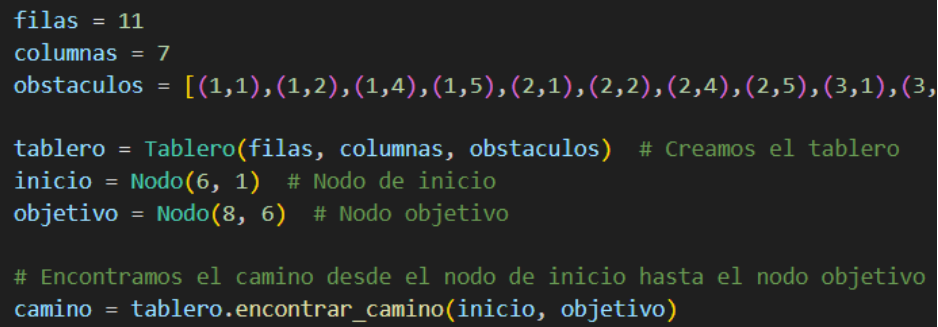

Dentro del método *encontrar_camino() *se crea una lista llamada *abiertos *la cual almacenará los nodos a explorar y se crea un conjunto llamado *cerrados* que almacenará los nodos ya explorados. Cabe aclarar que la lista es una colección de elementos de forma ordenada los cuales se pueden acceder utilizando un índice y el conjunto es una colección de elementos únicos no ordenados, esto quiere decir, que no se pueden acceder mediante índices y no se repiten. Luego de crear la lista y el conjunto, se procede a almacenar el nodo “inicio” a la lista *abiertos *utilizando la función *heappush *del módulo que se mencionó anteriormente “*headpq*” el cual tiene como parámetro una tupla con el costo total calculado en la clase *Nodo *y el objeto nodo.

Se utilizó el módulo “headpq” el cual proporciona funciones que permiten trabajar con colas de prioridad, los cuales falicitarán el orden de los elementos en una lista según el costo total que tengan

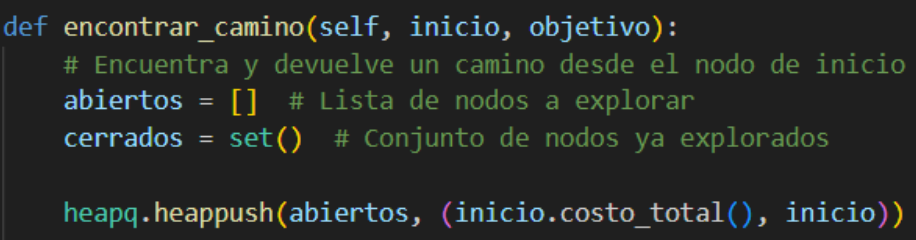

Mientras haya elementos en la lista *abiertos *se ejecutará el bucle *while*, en el cual se realizarán todos los cálculos necesarios para obtener el camino óptimo.De la lista *abiertos* se obtiene el nodo el nodo con menor costo total y luego se analiza si es el nodo objetivo. Si ese es el caso, se define una lista la cual almacenará las posiciones X e Y de los nodos que generaron el camino optimo para asi poder devolverlos a la funcion principal de donde se llamo a la funcion *encontrar_camino*. Para completar dicha lista, se analizan los nodos padres (*figura…*).

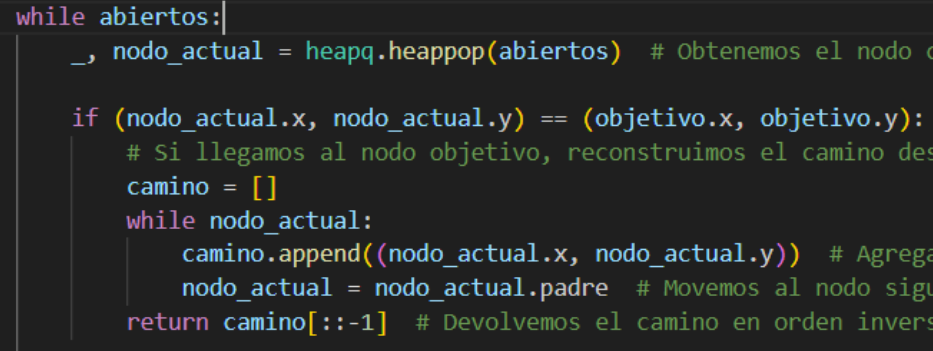

Si el nodo actual no es el objetivo, se procede a almacenarlo en el conjunto *cerrados*. Luego de este almacenamiento, se analizan los vecinos del conjunto (*figura*…) y se verifica antes de realizar cálculos si se puede avanzar o no dependiendo de las dimensiones del tablero y de los obstáculos (*figura…*).

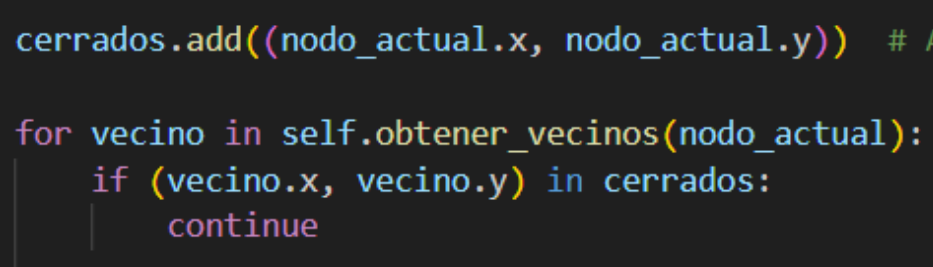   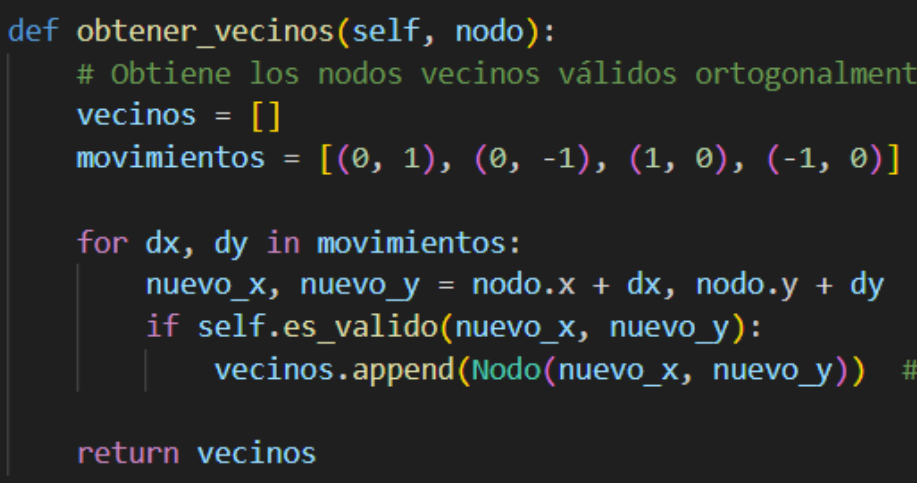

A una nueva variable llamada *nuevo_costo_g*, se le suma un valor de 1 ya que ese es el costo al avanzar una posición. Luego, si no se ha calculado el nodo vecino o el nodo vecino tiene un costo mayor a la variable *nuevo_costo_g*, entonces se procede a asignarle los atributos correspondientes a al nodo vecino (costo de ganancia y heuristica) y asignando el nodo analizado como el nodo padre de este vecino y finalmente se agrega este objeto a la lista *abiertos *(figura…).

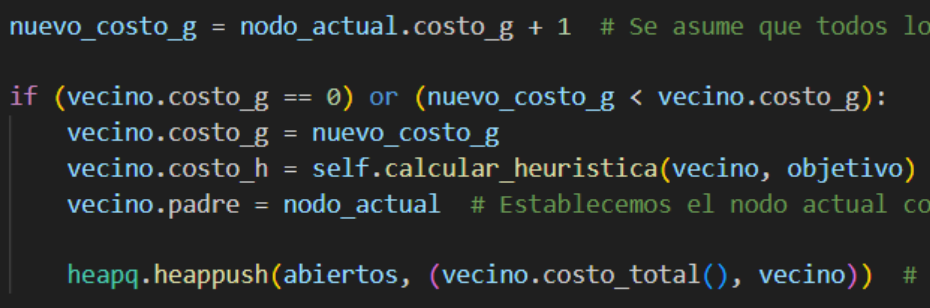

Se procede a seguir analizando los vecinos y los nodos con menor costo hasta alcanzar el camino óptimo.